# Machine Learning: Programming Exercise 4

## Neural Networks Learning

In this exercise, you will implement the backpropagation algorithm for neural networks and apply it to the task of hand-written digit recognition.

### Files needed for this exercise

- `ex4.mlx` - MATLAB Live Script that steps you through the exercise

- `ex4data1.mat` - Training set of hand-written digits

- `ex4weights.mat` - Neural network parameters for exercise 4

- `submit.m` - Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `computeNumericalGradient.m` - Numerically compute gradients

- `checkNNGradients.m` - Function to help check your gradients

- `debugInitializeWeights.m` - Function for initializing weights

- `predict.m` - Neural network prediction function

- *`sigmoidGradient.m` - Compute the gradient of the sigmoid function

- *`randInitializeWeights.m` - Randomly initialize weights

- *`nnCostFunction.m` - Neural network cost function

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex4' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Neural Networks

In the previous exercise, you implemented feedforward propagation for neural networks and used it to predict handwritten digits with the weights we provided. In this exercise, you will implement the backpropagation algorithm to learn the parameters for the neural network.

### 1.1 Visualizing the data

The code below will load the data and display it on a 2-dimensional plot (Figure 1) by calling the function `displayData`. This is the same dataset that you used in the previous exercise. Run the code below to load the training data into the variables `X` and `y.`

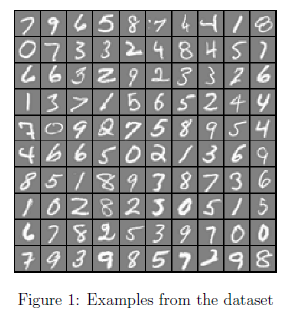

load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

    There are 5000 training examples in `ex4data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

### 1.2 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (not counting the extra bias unit which always outputs +1). 

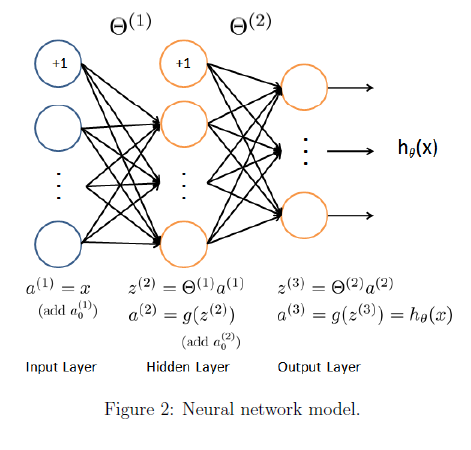

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex4weights.mat. ` Run the code below to load them into `Theta1` and `Theta2`. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 1.3 Feedforward and cost function

Now you will implement the cost function and gradient for the neural network. First, complete the code in `nnCostFunction.m` to return the cost. Recall that the cost function for the neural network (without regularization) is


$$J(\theta) =\frac{1}{m}{\sum_{i=1}^m\sum_{k=1}^K{\left[

-y_k^{(i)} \log((h_{\theta}(x^{(i)}))_k)- (1 -y_k^{(i)}) \log(1- (h_{\theta}(x^{(i)}))_k)\right]},$$


where $h_\theta(x^{(i)})$ is computed as shown in the Figure 2 and $K = 10$ is the total number of possible labels. Note that $h_\theta(x^{(i)})_k = a^{(3)}_k$ is the activation (output value) of the $k$-th output unit. Also, recall that whereas the original labels (in the variable `y`) were $1, 2, \ldots, 10,$ for the purpose of training a neural network, we need to recode the labels as vectors containing only values 0 or 1, so that


$$y=\left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
1\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\dots \textrm{or}\;\left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


    For example, if $x^{(i)}$ is an image of the digit 5, then the corresponding $y^{(i)}$ (that you should use with the cost function) should be a 10-dimensional vector with $y_5 = 1$, and the other elements equal to 0. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and sum the cost over all examples. Your code should also work for a dataset of any size, with any number of labels (you can assume that there are always at least $K\geq 3$ labels). 

**Implementation Note:** The matrix `X` contains the examples in rows (i.e., `X(i,:)'` is the `i`-th training example $x^{(i)}$, expressed as a $n$ x 1 vector.) When you complete the code in `nnCostFunction.m`, you will need to add the column of 1's to the `X` matrix. The parameters for each unit in the neural network is represented in `Theta1` and `Theta2` as one row. Specifically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. You can use a `for` loop over the examples to compute the cost.  We suggest implementing the feedforward cost *without* regularization first so that it will be easier for you to debug. Later, you will get to implement the regularized cost.

    Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the cost is about 0.287629.

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.287629

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 Regularized cost function

The cost function for neural networks with regularization is given by


$$J(\theta) =
\frac{1}{m}\sum_{i=1}^m
\sum_{k=1}^K 
\left[ -y^{(i)}_k \log((h_{\theta}(x^{(i)})_k)- (1 -y^{(i)}_k) \log(1-(h_{\theta}(x^{(i)}))_k)  \right]
\\ \qquad 
+\frac{\lambda}{2m} \left[\sum_{j=1}^{25} 
\sum_{k=1}^{400} {\left( \Theta_{j,k}^{(1)}\right)^2}+
\sum_{j=1}^{10} 
\sum_{k=1}^{25} {\left( \Theta_{j,k}^{(2)}\right)^2}\right]$$


You can assume that the neural network will only have 3 layers- an input layer, a hidden layer and an output layer. However, your code should work for any number of input units, hidden units and outputs units. While we have explicitly listed the indices above for $\Theta^{(1)}$ and $\Theta^{(2)}$ for clarity, do note that** your code should in general work with **$\Theta^{(1)}$ and $\Theta^{(2)}$ **of any size.**

    Note that you should not be regularizing the terms that correspond to the bias. For the matrices Theta1 and Theta2, this corresponds to the first column of each matrix. You should now add regularization to your cost function. Notice that you can first compute the unregularized cost function $J$ using your existing `nnCostFunction.m` and then later add the cost for the regularization terms. Once you are done, run the code below to call your `nnCostFunction` using the loaded set of parameters for `Theta1` and `Theta2`, and $\lambda= 1$. You should see that the cost is about 0.383770.

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.383770

*You should now submit your solutions.  Enter/confirm your login and token in the command window when prompted.*

## 2. Backpropagation

In this part of the exercise, you will implement the backpropagation algorithm to compute the gradient for the neural network cost function. You will need to complete the `nnCostFunction.m` so that it returns an appropriate value for `grad`. Once you have computed the gradient, you will be able to train the neural network by minimizing the cost function $J(\theta)$ using an advanced optimizer such as `fmincg`.

    You will first implement the backpropagation algorithm to compute the gradients for the parameters for the (unregularized) neural network. After you have verified that your gradient computation for the unregularized case is correct, you will implement the gradient for the regularized neural network.

### 2.1 Sigmoid gradient

To help you get started with this part of the exercise, you will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


When you are done, try testing a few values by calling `sigmoidGradient(z)` below. For large values (both positive and negative) of `z`, the gradient should be close to 0. When `z = 0`, the gradient should be exactly 0.25. Your code should also work with vectors and matrices. For a matrix, your function should perform the sigmoid gradient function on every element.

% Call your sigmoidGradient function
sigmoidGradient(0)

g = 0.2500

ans = 0.2500

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.2 Random initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient. 

Your job is to complete `randInitializeWeights.m` to initialize the weights for $\Theta$; modify the file and fill in the following code:

When you are done, run the code below to call `randInitialWeights` and initialize the neural network parameters.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

*One effective strategy for choosing $\epsilon_{init}$ is to base it on the number of units in the network. A good choice of $\epsilon_{init}$ is $\epsilon_{init} = \frac{\sqrt{6}}{\sqrt{L_{in}+L_{out}}},$ where $L_{in} = s_l$ and $L_{out} = s_{l+1}$ are the number of units in the layers adjacent to $\Theta^{(l)}$.

*You do not need to submit any code for this part of the exercise.*

### 2.3 Backpropagation

Now, you will implement the backpropagation algorithm. Recall that the intuition behind the backpropagation algorithm is as follows. Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

    For an output node, we can directly measure the difference between the network's activation and the true target value, and use that to define $\delta^{(3)}_j$ (since layer 3 is the output layer). For the hidden units, you will compute $\delta^{(l)}_j$ based on a weighted average of the error terms of the nodes in layer $(l + 1)$.

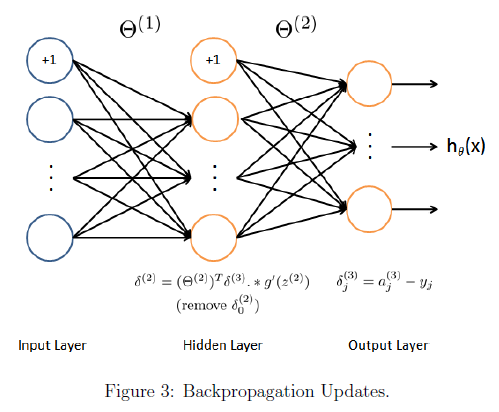

    In detail, here is the backpropagation algorithm (also depicted in Figure 3). You should implement steps 1 to 4 in a loop that processes one example at a time. Concretely, you should implement a `for` loop for `t = 1:m` and place steps 1-4 below inside the `for` loop, with the $t^{th}$ iteration performing the calculation on the $t^{th}$ training example $(x^{(t)}, y^{(t)})$. Step 5 will divide the accumulated gradients by $m$ to obtain the gradients for the neural network cost function.

- Set the input layer's values $(a^{(1)})$ to the $t$-th training example $x^{(t)}$. Perform a feedforward pass (Figure 2), computing the activations $(z^{(2)}, a^{(2)}, z^{(3)}, a^{(3)})$ for layers 2 and 3. Note that you need to add a $+1$ term to ensure that the vectors of activations for layers $a^{(1)}$ and $a^{(2)}$ also include the bias unit. In MATLAB, if `a_1` is a column vector, adding one corresponds to `a_1 = [1; a_1].`

- For each output unit $k$ in layer 3 (the output layer), set $\delta^{(3)}_k = (a_k^{(3)}-y_k)$ where $y_k\in \{0, 1\}$ indicates whether the current training example belongs to class $k$ $(y_k = 1)$, or if it belongs to a different class $(y_k = 0)$.You may find logical arrays helpful for this task (explained in the previous programming exercise).

- For the hidden layer $l = 2$, set $\delta^{(2)} = (\Theta^{(2)})^T \delta^{(3)}.*g'(z^{(2)})$

- Accumulate the gradient from this example using the following formula: $\Delta^{(l)} = \Delta^{(l)} + \delta^{(l+1)} (a^{(l)})^T$. Note that you should skip or remove $\delta_0^{(2)}$. In MATLAB, removing $\delta_0^{(2)}$ corresponds to `delta_2 = delta_2(2:end).`

- Obtain the (unregularized) gradient for the neural network cost function by dividing the accumulated gradients by $\frac{1}{m}:$ $\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij}$

**MATLAB Tip:** You should implement the backpropagation algorithm only after you have successfully completed the feedforward and cost functions. While implementing the backpropagation algorithm, it is often useful to use the size function to print out the sizes of the variables you are working with if you run into dimension mismatch errors (''nonconformant arguments") errors.

    After you have implemented the backpropagation algorithm, the code in the next section will run gradient checking on your implementation. The gradient check will allow you to increase your confidence that your code is computing the gradients correctly.

### 2.4 Gradient checking

In your neural network, you are minimizing the cost function $J(\Theta)$. To perform gradient checking on your parameters, you can imagine 'unrolling' the parameters $\Theta^{(1)},\Theta^{(2)}$ into a long vector $\theta$. By doing so, you can think of the cost function being $J(\theta)$ instead and use the following gradient checking procedure.

    Suppose you have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; you'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. You can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, you'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). We have implemented the function to compute the numerical gradient for you in `computeNumericalGradient.m`. While you are not required to modify the file, we highly encourage you to take a look at the code to understand how it works.

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

**Practical Tip:** When performing gradient checking, it is much more efficient to use a small neural network with a relatively small number of input units and hidden units, thus having a relatively small number of parameters. Each dimension of $\theta$ requires two evaluations of the cost function and this can be expensive. In the function `checkNNGradients`, our code creates a small random model and dataset which is used with `computeNumericalGradient` for gradient checking. Furthermore, after you are condent that your gradient computations are correct, you should turn off gradient checking before running your learning algorithm.

**Practical Tip: **Gradient checking works for any function where you are computing the cost and the gradient. Concretely, you can use the same `computeNumericalGradient.m` function to check if your gradient implementations for the other exercises are correct too (e.g. logistic regression's cost function). Once your cost function passes the gradient check for the (unregularized) neural network cost function, you should submit the neural network gradient function (backpropagation).

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.5 Regularized neural networks

After you have successfully implemeted the backpropagation algorithm, you will add regularization to the gradient. To account for regularization, it turns out that you can add this as an additional term after computing the gradients using backpropagation. Specically, after you have computed $\Delta^{(l)}_{ij}
$ using backpropagation, you should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that you should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

    Now, modify your code that computes `grad` in `nnCostFunction` to account for regularization. After you are done, run the code below to run gradient checking on your implementation. If your code is correct, you should expect to see a relative difference that is less than 1e-9.

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g =     0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


g = 5×5
    0.2495    0.2496    0.2497    0.2496    0.2495
    0.2493    0.2494    0.2496    0.2497    0.2496
    0.2499    0.2499    0.2500    0.2500    0.2500
    0.2496    0.2497    0.2497    0.2497    0.2496
    0.2492    0.2494    0.2495    0.2496    0.2495


   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

g = 25×5000
    0.0478    0.0080    0.0140    0.0438    0.0019    0.0040    0.0060    0.0058    0.0036    0.0024    0.0033    0.0236    0.0093    0.0630    0.0028    0.0277    0.0025    0.0002    0.0166    0.0035    0.1371    0.0016    0.0034    0.0865    0.0238    0.0111    0.2368    0.0481    0.0062    0.0078
    0.0731    0.0484    0.0238    0.0036    0.0717    0.0006    0.0100    0.0119    0.0427    0.2482    0.2051    0.0070    0.0510    0.0006    0.0192    0.0420    0.0280    0.0010    0.1494    0.1876    0.0070    0.0802    0.0216    0.0958    0.1835    0.0030    0.0453    0.0487    0.0390    0.0098
    0.0069    0.0619    0.0025    0.0043    0.0113    0.0001    0.1195    0.0029    0.0041    0.1632    0.0049    0.0051    0.0027    0.0008    0.0007    0.0041    0.0028    0.0000    0.0037    0.0082    0.0032    0.0020    0.0007    0.0198    0.0032    0.0024    0.0181    0.0491    0.0012    0.0006
    0.2496    0.2099    0.1022    0.0909    0.2133    0.2482    0.1129    0.1270    0

fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.6 Learning parameters using `fmincg`

After you have successfully implemented the neural network cost function and gradient computation, run the code below to use `fmincg` to learn a good set of parameters. After the training completes, the code will report the training accuracy of your classifier by computing the percentage of examples it got correct. If your implementation is correct, you should see a reported training accuracy of about 95.3% (this may vary by about 1% due to the random initialization). It is possible to get higher training accuracies by training the neural network for more iterations. 

options = optimset('MaxIter', 50);
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

g =     0.2378    0.2415    0.2493    0.2488    0.2480    0.2499    0.2306    0.2076    0.2425    0.2455    0.2456    0.2499    0.2467    0.2305    0.2446    0.2324    0.2464    0.2494    0.2459    0.2439    0.2494    0.2456    0.2493    0.2490    0.2500    0.2498    0.2495    0.2429    0.2435    0.2477    0.2468    0.2492    0.2344    0.2475    0.2423    0.2493    0.2448    0.2457    0.2412    0.2468    0.2450    0.2428    0.2419    0.2480    0.2414    0.2493    0.2491    0.2290    0.2457    0.2493
    0.2499    0.2497    0.2329    0.2197    0.2403    0.2458    0.2264    0.2482    0.2342    0.2444    0.2484    0.2484    0.2414    0.2310    0.2353    0.2439    0.2342    0.2494    0.2483    0.2311    0.2498    0.2490    0.2470    0.2468    0.2437    0.2447    0.2442    0.2486    0.2430    0.2469    0.2432    0.2470    0.2400    0.2392    0.2382    0.2416    0.2479    0.2489    0.2111    0.2312    0.2500    0.2439    0.2500    0.2232    0.2295    0.2487    0.2380    0.2496    0.2164    0

g =     0.2357    0.2395    0.2498    0.2478    0.2468    0.2496    0.2271    0.2093    0.2400    0.2439    0.2438    0.2497    0.2452    0.2321    0.2429    0.2304    0.2449    0.2488    0.2449    0.2419    0.2489    0.2443    0.2488    0.2487    0.2499    0.2495    0.2497    0.2414    0.2442    0.2484    0.2472    0.2484    0.2313    0.2465    0.2400    0.2486    0.2434    0.2443    0.2387    0.2450    0.2434    0.2411    0.2436    0.2469    0.2398    0.2486    0.2483    0.2313    0.2445    0.2489
    0.2500    0.2495    0.2348    0.2220    0.2387    0.2449    0.2287    0.2485    0.2361    0.2454    0.2490    0.2479    0.2428    0.2320    0.2368    0.2431    0.2360    0.2497    0.2487    0.2330    0.2499    0.2486    0.2476    0.2464    0.2445    0.2438    0.2447    0.2481    0.2425    0.2475    0.2436    0.2476    0.2414    0.2403    0.2397    0.2428    0.2473    0.2493    0.2137    0.2334    0.2499    0.2448    0.2499    0.2253    0.2308    0.2482    0.2394    0.2498    0.2181    0

g =     0.2311    0.2351    0.2499    0.2450    0.2435    0.2481    0.2195    0.2126    0.2342    0.2402    0.2396    0.2487    0.2411    0.2350    0.2391    0.2263    0.2409    0.2469    0.2427    0.2369    0.2472    0.2415    0.2471    0.2477    0.2492    0.2483    0.2500    0.2380    0.2455    0.2494    0.2480    0.2463    0.2244    0.2440    0.2347    0.2465    0.2403    0.2410    0.2328    0.2403    0.2395    0.2373    0.2464    0.2437    0.2362    0.2466    0.2460    0.2357    0.2417    0.2479
    0.2499    0.2487    0.2383    0.2263    0.2353    0.2426    0.2330    0.2489    0.2397    0.2471    0.2497    0.2468    0.2452    0.2338    0.2396    0.2415    0.2392    0.2500    0.2493    0.2367    0.2500    0.2476    0.2486    0.2455    0.2459    0.2419    0.2457    0.2471    0.2415    0.2484    0.2443    0.2487    0.2439    0.2423    0.2425    0.2449    0.2461    0.2498    0.2187    0.2374    0.2495    0.2463    0.2494    0.2294    0.2334    0.2470    0.2420    0.2500    0.2213    0

g =     0.2151    0.2187    0.2436    0.2313    0.2282    0.2390    0.1940    0.2217    0.2117    0.2251    0.2222    0.2425    0.2239    0.2420    0.2239    0.2127    0.2242    0.2370    0.2344    0.2174    0.2382    0.2305    0.2387    0.2439    0.2441    0.2414    0.2491    0.2256    0.2484    0.2495    0.2494    0.2356    0.2004    0.2337    0.2142    0.2353    0.2282    0.2279    0.2107    0.2195    0.2240    0.2231    0.2500    0.2292    0.2235    0.2361    0.2344    0.2453    0.2306    0.2432
    0.2480    0.2444    0.2459    0.2371    0.2234    0.2343    0.2430    0.2498    0.2472    0.2498    0.2493    0.2422    0.2494    0.2387    0.2459    0.2361    0.2463    0.2490    0.2500    0.2449    0.2486    0.2434    0.2500    0.2425    0.2488    0.2350    0.2480    0.2430    0.2382    0.2499    0.2462    0.2500    0.2488    0.2468    0.2481    0.2489    0.2410    0.2495    0.2315    0.2460    0.2463    0.2493    0.2462    0.2393    0.2398    0.2416    0.2474    0.2491    0.2300    0

Iteration     1 | Cost: 3.308140e+00


g =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0015    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0000    0.0000    0.0000    0.0000    0.0010    0.0000    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

g =     0.0278    0.0233    0.0227    0.0188    0.0141    0.0250    0.0085    0.2171    0.0089    0.0220    0.0152    0.0460    0.0136    0.1617    0.0225    0.0442    0.0153    0.0288    0.0651    0.0130    0.0347    0.0395    0.0384    0.1134    0.0570    0.0429    0.1187    0.0370    0.1754    0.0736    0.1992    0.0249    0.0092    0.0389    0.0116    0.0244    0.0372    0.0288    0.0103    0.0079    0.0195    0.0291    0.0476    0.0185    0.0412    0.0242    0.0234    0.0781    0.0422    0.0920
    0.0788    0.0748    0.0270    0.0212    0.0745    0.0829    0.0248    0.1574    0.0208    0.0508    0.0424    0.1039    0.0283    0.0949    0.0448    0.1435    0.0289    0.0548    0.1139    0.0237    0.0597    0.1210    0.0683    0.1943    0.0756    0.1203    0.1074    0.1004    0.2186    0.0941    0.1671    0.0444    0.0221    0.0518    0.0243    0.0374    0.1067    0.0721    0.0136    0.0132    0.0566    0.0581    0.0619    0.0214    0.0546    0.0700    0.0365    0.0688    0.0442    0

g =     0.1545    0.1536    0.1833    0.1614    0.1510    0.1781    0.1111    0.2425    0.1254    0.1585    0.1467    0.1981    0.1458    0.2498    0.1578    0.1640    0.1489    0.1788    0.1957    0.1386    0.1850    0.1786    0.1882    0.2221    0.2061    0.1948    0.2332    0.1717    0.2482    0.2251    0.2484    0.1733    0.1174    0.1819    0.1332    0.1726    0.1746    0.1680    0.1278    0.1295    0.1544    0.1633    0.2213    0.1586    0.1723    0.1733    0.1704    0.2421    0.1805    0.2160
    0.2387    0.2424    0.1921    0.1716    0.2497    0.2483    0.1843    0.2410    0.1891    0.2193    0.2250    0.2472    0.2040    0.2105    0.2039    0.2500    0.1944    0.2306    0.2374    0.1869    0.2331    0.2478    0.2276    0.2500    0.2229    0.2498    0.2280    0.2465    0.2485    0.2323    0.2348    0.2201    0.1955    0.2092    0.1955    0.2082    0.2479    0.2335    0.1538    0.1753    0.2364    0.2191    0.2379    0.1748    0.1983    0.2437    0.2028    0.2341    0.1808    0

g =     0.1782    0.1793    0.2110    0.1904    0.1823    0.2047    0.1408    0.2361    0.1578    0.1853    0.1766    0.2182    0.1768    0.2493    0.1843    0.1830    0.1790    0.2039    0.2121    0.1691    0.2082    0.2002    0.2103    0.2319    0.2236    0.2157    0.2414    0.1936    0.2499    0.2382    0.2497    0.1999    0.1476    0.2038    0.1641    0.1993    0.1967    0.1926    0.1590    0.1641    0.1823    0.1873    0.2383    0.1875    0.1930    0.2002    0.1975    0.2491    0.2013    0.2282
    0.2475    0.2493    0.2177    0.1998    0.2473    0.2495    0.2110    0.2458    0.2174    0.2362    0.2417    0.2500    0.2281    0.2226    0.2239    0.2481    0.2193    0.2441    0.2449    0.2141    0.2453    0.2500    0.2407    0.2487    0.2362    0.2485    0.2378    0.2500    0.2457    0.2423    0.2399    0.2378    0.2228    0.2274    0.2219    0.2293    0.2499    0.2446    0.1859    0.2087    0.2474    0.2351    0.2478    0.2031    0.2165    0.2498    0.2248    0.2453    0.2012    0

Iteration     2 | Cost: 3.249947e+00


g =     0.1341    0.1317    0.1742    0.1487    0.1079    0.1447    0.0865    0.2473    0.1010    0.1340    0.1195    0.1683    0.1207    0.2482    0.1255    0.1406    0.1205    0.1515    0.1751    0.1197    0.1608    0.1462    0.1578    0.2068    0.1855    0.1636    0.2270    0.1418    0.2416    0.2049    0.2476    0.1370    0.0854    0.1610    0.1032    0.1515    0.1489    0.1362    0.1054    0.1044    0.1173    0.1345    0.2045    0.1453    0.1517    0.1287    0.1419    0.2330    0.1606    0.2088
    0.2461    0.2491    0.2117    0.1795    0.2450    0.2484    0.2182    0.2431    0.2101    0.2372    0.2392    0.2497    0.2170    0.2116    0.2235    0.2497    0.2101    0.2313    0.2437    0.2027    0.2285    0.2488    0.2342    0.2482    0.2302    0.2473    0.2219    0.2474    0.2454    0.2418    0.2368    0.2154    0.1864    0.2057    0.1978    0.2138    0.2500    0.2441    0.1482    0.1747    0.2392    0.2249    0.2389    0.1785    0.1969    0.2465    0.2108    0.2327    0.1818    0

g =     0.1602    0.1599    0.1968    0.1737    0.1511    0.1812    0.1171    0.2416    0.1336    0.1645    0.1530    0.1994    0.1536    0.2500    0.1602    0.1659    0.1548    0.1834    0.1979    0.1486    0.1898    0.1788    0.1901    0.2227    0.2095    0.1959    0.2364    0.1729    0.2481    0.2268    0.2491    0.1749    0.1203    0.1871    0.1382    0.1805    0.1777    0.1699    0.1363    0.1388    0.1554    0.1660    0.2267    0.1706    0.1765    0.1715    0.1754    0.2449    0.1853    0.2209
    0.2470    0.2492    0.2153    0.1918    0.2464    0.2491    0.2140    0.2448    0.2145    0.2366    0.2407    0.2500    0.2239    0.2184    0.2237    0.2489    0.2157    0.2398    0.2444    0.2096    0.2399    0.2498    0.2383    0.2485    0.2339    0.2481    0.2320    0.2494    0.2456    0.2421    0.2387    0.2299    0.2092    0.2193    0.2128    0.2235    0.2500    0.2444    0.1707    0.1955    0.2448    0.2313    0.2450    0.1935    0.2090    0.2489    0.2194    0.2411    0.1935    0

Iteration     3 | Cost: 3.224193e+00


g =     0.1397    0.1382    0.1820    0.1557    0.1157    0.1518    0.0933    0.2464    0.1085    0.1414    0.1272    0.1742    0.1280    0.2489    0.1319    0.1456    0.1278    0.1578    0.1794    0.1271    0.1665    0.1523    0.1639    0.2102    0.1909    0.1698    0.2296    0.1480    0.2432    0.2094    0.2480    0.1436    0.0914    0.1661    0.1098    0.1581    0.1546    0.1426    0.1120    0.1113    0.1238    0.1401    0.2098    0.1518    0.1566    0.1358    0.1483    0.2359    0.1657    0.2113
    0.2484    0.2500    0.2213    0.1913    0.2409    0.2461    0.2264    0.2448    0.2205    0.2420    0.2442    0.2500    0.2262    0.2162    0.2300    0.2487    0.2195    0.2372    0.2459    0.2133    0.2350    0.2475    0.2386    0.2472    0.2352    0.2452    0.2270    0.2491    0.2441    0.2444    0.2389    0.2235    0.1987    0.2137    0.2088    0.2224    0.2496    0.2469    0.1616    0.1888    0.2437    0.2309    0.2435    0.1906    0.2049    0.2487    0.2193    0.2378    0.1903    0

g =     0.1022    0.0991    0.1514    0.1212    0.0616    0.0984    0.0565    0.2500    0.0680    0.0996    0.0831    0.1236    0.0841    0.2407    0.0834    0.1081    0.0819    0.1097    0.1416    0.0892    0.1210    0.1034    0.1136    0.1813    0.1511    0.1184    0.2129    0.1024    0.2258    0.1678    0.2444    0.0888    0.0494    0.1252    0.0650    0.1154    0.1113    0.0941    0.0719    0.0675    0.0725    0.0941    0.1693    0.1161    0.1187    0.0765    0.0992    0.2074    0.1271    0.1900
    0.2499    0.2486    0.2318    0.1902    0.2231    0.2340    0.2442    0.2448    0.2312    0.2487    0.2487    0.2497    0.2305    0.2119    0.2403    0.2482    0.2266    0.2313    0.2483    0.2203    0.2229    0.2357    0.2394    0.2435    0.2376    0.2358    0.2156    0.2483    0.2406    0.2479    0.2392    0.2089    0.1762    0.2015    0.2005    0.2203    0.2475    0.2497    0.1435    0.1749    0.2413    0.2300    0.2397    0.1847    0.1964    0.2483    0.2192    0.2299    0.1838    0

g =     0.0331    0.0298    0.0741    0.0480    0.0067    0.0191    0.0104    0.2149    0.0136    0.0277    0.0182    0.0313    0.0187    0.1817    0.0159    0.0364    0.0167    0.0274    0.0556    0.0256    0.0350    0.0240    0.0273    0.0958    0.0575    0.0284    0.1504    0.0260    0.1420    0.0613    0.2245    0.0149    0.0062    0.0421    0.0105    0.0352    0.0323    0.0203    0.0155    0.0118    0.0107    0.0219    0.0639    0.0435    0.0421    0.0094    0.0220    0.1002    0.0463    0.1221
    0.2442    0.2234    0.2495    0.1868    0.1431    0.1668    0.2231    0.2449    0.2493    0.2342    0.2425    0.2454    0.2412    0.1979    0.2486    0.2464    0.2429    0.2087    0.2494    0.2376    0.1746    0.1644    0.2416    0.2238    0.2437    0.1864    0.1743    0.2445    0.2256    0.2482    0.2402    0.1573    0.1099    0.1613    0.1739    0.2135    0.2310    0.2409    0.0948    0.1334    0.2320    0.2275    0.2243    0.1669    0.1695    0.2467    0.2187    0.1979    0.1638    0

g =     0.0190    0.0165    0.0510    0.0301    0.0024    0.0085    0.0047    0.1840    0.0063    0.0148    0.0087    0.0156    0.0091    0.1485    0.0072    0.0212    0.0077    0.0137    0.0343    0.0139    0.0187    0.0117    0.0134    0.0673    0.0345    0.0139    0.1226    0.0132    0.1053    0.0354    0.2118    0.0063    0.0024    0.0243    0.0044    0.0194    0.0174    0.0096    0.0074    0.0052    0.0043    0.0108    0.0375    0.0266    0.0250    0.0034    0.0105    0.0648    0.0277    0.0956
    0.2369    0.2043    0.2492    0.1853    0.1081    0.1329    0.1849    0.2449    0.2494    0.2131    0.2306    0.2419    0.2447    0.1912    0.2405    0.2455    0.2473    0.1967    0.2471    0.2432    0.1508    0.1284    0.2425    0.2116    0.2458    0.1595    0.1545    0.2421    0.2172    0.2434    0.2406    0.1338    0.0852    0.1430    0.1616    0.2102    0.2194    0.2293    0.0770    0.1160    0.2270    0.2264    0.2157    0.1588    0.1572    0.2458    0.2185    0.1810    0.1547    0

Iteration     4 | Cost: 2.745395e+00


g =     0.0028    0.0022    0.0161    0.0068    0.0001    0.0005    0.0003    0.0841    0.0005    0.0017    0.0007    0.0013    0.0008    0.0638    0.0004    0.0030    0.0005    0.0013    0.0057    0.0019    0.0020    0.0009    0.0011    0.0169    0.0054    0.0011    0.0556    0.0012    0.0296    0.0048    0.1664    0.0003    0.0001    0.0035    0.0002    0.0025    0.0019    0.0007    0.0006    0.0003    0.0002    0.0009    0.0058    0.0053    0.0039    0.0001    0.0008    0.0133    0.0045    0.0389
    0.1944    0.1226    0.2114    0.1700    0.0283    0.0433    0.0534    0.2439    0.2102    0.1110    0.1604    0.2234    0.2499    0.1584    0.1661    0.2431    0.2464    0.1373    0.2248    0.2498    0.0674    0.0370    0.2434    0.1570    0.2497    0.0716    0.0822    0.2261    0.1786    0.2044    0.2414    0.0570    0.0245    0.0770    0.1066    0.1895    0.1661    0.1642    0.0277    0.0557    0.1957    0.2156    0.1659    0.1212    0.1049    0.2384    0.2125    0.1085    0.1148    0

Iteration     5 | Cost: 2.466939e+00


g =     0.0021    0.0017    0.0144    0.0058    0.0000    0.0003    0.0002    0.0786    0.0003    0.0013    0.0005    0.0010    0.0006    0.0611    0.0003    0.0023    0.0004    0.0010    0.0045    0.0015    0.0016    0.0006    0.0008    0.0141    0.0042    0.0008    0.0520    0.0009    0.0252    0.0039    0.1633    0.0002    0.0001    0.0029    0.0002    0.0021    0.0014    0.0004    0.0005    0.0002    0.0001    0.0007    0.0051    0.0047    0.0030    0.0001    0.0006    0.0126    0.0035    0.0364
    0.1898    0.1127    0.2139    0.1544    0.0206    0.0342    0.0422    0.2435    0.2027    0.0971    0.1520    0.2170    0.2498    0.1484    0.1493    0.2441    0.2457    0.1234    0.2185    0.2500    0.0539    0.0273    0.2441    0.1459    0.2499    0.0581    0.0681    0.2225    0.1689    0.1933    0.2407    0.0463    0.0179    0.0663    0.0919    0.1799    0.1584    0.1540    0.0197    0.0431    0.1883    0.2107    0.1499    0.1081    0.0908    0.2382    0.2100    0.0947    0.1028    0

Iteration     6 | Cost: 2.192524e+00


g =     0.0019    0.0015    0.0148    0.0061    0.0000    0.0003    0.0002    0.0956    0.0003    0.0011    0.0004    0.0012    0.0005    0.0797    0.0002    0.0022    0.0003    0.0014    0.0042    0.0014    0.0017    0.0007    0.0011    0.0148    0.0042    0.0009    0.0574    0.0010    0.0281    0.0050    0.1706    0.0003    0.0001    0.0037    0.0002    0.0024    0.0012    0.0004    0.0005    0.0003    0.0002    0.0007    0.0073    0.0056    0.0027    0.0001    0.0006    0.0214    0.0033    0.0420
    0.1450    0.0688    0.1956    0.1706    0.0061    0.0142    0.0182    0.2499    0.1307    0.0513    0.0962    0.1523    0.2378    0.1596    0.0805    0.2260    0.2084    0.1559    0.1709    0.2359    0.0617    0.0104    0.2443    0.1051    0.2369    0.0252    0.0643    0.2475    0.1263    0.1319    0.2470    0.0606    0.0225    0.0853    0.1194    0.2138    0.1100    0.1006    0.0199    0.0531    0.2323    0.2387    0.1728    0.1359    0.0985    0.2450    0.2463    0.1161    0.1188    0

Iteration     7 | Cost: 1.858679e+00


g =     0.0034    0.0027    0.0359    0.0146    0.0001    0.0007    0.0004    0.1572    0.0009    0.0019    0.0008    0.0031    0.0013    0.1497    0.0004    0.0035    0.0006    0.0048    0.0066    0.0032    0.0039    0.0015    0.0034    0.0233    0.0076    0.0022    0.0914    0.0021    0.0464    0.0127    0.2038    0.0009    0.0002    0.0092    0.0004    0.0065    0.0019    0.0006    0.0012    0.0009    0.0005    0.0017    0.0233    0.0153    0.0042    0.0002    0.0015    0.0740    0.0058    0.0745
    0.1042    0.0400    0.1832    0.1848    0.0017    0.0057    0.0076    0.2453    0.0708    0.0249    0.0560    0.0871    0.2007    0.1718    0.0379    0.1977    0.1509    0.1937    0.1195    0.2027    0.0723    0.0036    0.1983    0.0713    0.1947    0.0101    0.0600    0.2433    0.0868    0.0781    0.2499    0.0815    0.0294    0.1128    0.1542    0.2393    0.0714    0.0608    0.0203    0.0662    0.2499    0.2500    0.1973    0.1660    0.1067    0.1877    0.2392    0.1443    0.1370    0

Iteration     8 | Cost: 1.630961e+00


g =     0.0046    0.0036    0.0669    0.0269    0.0001    0.0017    0.0006    0.2485    0.0018    0.0024    0.0009    0.0142    0.0025    0.2500    0.0004    0.0055    0.0007    0.0322    0.0096    0.0052    0.0091    0.0054    0.0212    0.0435    0.0127    0.0086    0.1439    0.0061    0.1042    0.0568    0.2325    0.0055    0.0007    0.0329    0.0010    0.0207    0.0022    0.0007    0.0026    0.0029    0.0026    0.0057    0.1171    0.0394    0.0048    0.0008    0.0041    0.2498    0.0087    0.1414
    0.0211    0.0048    0.0897    0.2499    0.0000    0.0003    0.0004    0.1580    0.0046    0.0018    0.0055    0.0081    0.0432    0.2304    0.0023    0.0772    0.0204    0.2245    0.0234    0.0514    0.1689    0.0001    0.0346    0.0168    0.0438    0.0005    0.0696    0.0847    0.0210    0.0098    0.2243    0.2213    0.1160    0.2425    0.2406    0.1740    0.0115    0.0078    0.0503    0.2047    0.0851    0.1307    0.2429    0.2460    0.1857    0.0191    0.0500    0.2479    0.2359    0

Iteration     9 | Cost: 1.542247e+00


g =     0.0014    0.0009    0.0178    0.0070    0.0000    0.0007    0.0001    0.2458    0.0004    0.0005    0.0002    0.0168    0.0007    0.2397    0.0001    0.0029    0.0001    0.0426    0.0047    0.0011    0.0051    0.0051    0.0307    0.0387    0.0058    0.0082    0.1123    0.0050    0.1234    0.0743    0.2116    0.0069    0.0004    0.0303    0.0003    0.0121    0.0007    0.0002    0.0007    0.0010    0.0029    0.0044    0.1342    0.0154    0.0015    0.0008    0.0020    0.2178    0.0034    0.1210
    0.0072    0.0012    0.0816    0.2440    0.0000    0.0000    0.0000    0.0985    0.0008    0.0003    0.0012    0.0014    0.0148    0.2403    0.0003    0.0366    0.0049    0.1460    0.0065    0.0213    0.2128    0.0000    0.0082    0.0056    0.0121    0.0001    0.0545    0.0285    0.0066    0.0022    0.1908    0.2497    0.1806    0.2354    0.1624    0.1031    0.0032    0.0019    0.0567    0.2466    0.0259    0.0603    0.2097    0.2067    0.2138    0.0028    0.0109    0.2411    0.2495    0

Iteration    10 | Cost: 1.367500e+00


g =     0.0006    0.0003    0.0059    0.0020    0.0000    0.0005    0.0000    0.1957    0.0002    0.0001    0.0000    0.0316    0.0002    0.1829    0.0000    0.0020    0.0000    0.0870    0.0028    0.0003    0.0035    0.0084    0.0714    0.0457    0.0035    0.0125    0.0967    0.0058    0.1790    0.1370    0.1825    0.0130    0.0003    0.0358    0.0002    0.0106    0.0003    0.0001    0.0002    0.0004    0.0052    0.0047    0.1953    0.0071    0.0005    0.0012    0.0012    0.1071    0.0015    0.1049
    0.0035    0.0005    0.1145    0.2498    0.0000    0.0000    0.0000    0.0797    0.0003    0.0001    0.0004    0.0004    0.0090    0.2198    0.0001    0.0231    0.0019    0.1335    0.0024    0.0155    0.2046    0.0000    0.0036    0.0024    0.0046    0.0000    0.0271    0.0155    0.0026    0.0009    0.1669    0.2500    0.1691    0.2177    0.1276    0.0989    0.0013    0.0007    0.0386    0.2478    0.0155    0.0426    0.2267    0.2108    0.2084    0.0008    0.0036    0.2483    0.2427    0

g =     0.0010    0.0006    0.0119    0.0045    0.0000    0.0006    0.0001    0.2329    0.0003    0.0003    0.0001    0.0212    0.0005    0.2231    0.0001    0.0025    0.0001    0.0559    0.0039    0.0007    0.0044    0.0062    0.0422    0.0411    0.0048    0.0096    0.1064    0.0053    0.1431    0.0943    0.2014    0.0087    0.0004    0.0322    0.0003    0.0115    0.0005    0.0001    0.0005    0.0008    0.0036    0.0045    0.1563    0.0116    0.0010    0.0009    0.0016    0.1780    0.0025    0.1150
    0.0056    0.0009    0.0928    0.2471    0.0000    0.0000    0.0000    0.0913    0.0005    0.0002    0.0008    0.0009    0.0124    0.2339    0.0002    0.0310    0.0035    0.1414    0.0046    0.0190    0.2099    0.0000    0.0061    0.0041    0.0085    0.0000    0.0424    0.0229    0.0047    0.0016    0.1822    0.2498    0.1764    0.2296    0.1494    0.1015    0.0024    0.0013    0.0494    0.2471    0.0215    0.0532    0.2163    0.2082    0.2119    0.0017    0.0073    0.2443    0.2479    0

Iteration    11 | Cost: 1.284982e+00


g =     0.0007    0.0004    0.0081    0.0027    0.0000    0.0006    0.0000    0.2103    0.0002    0.0002    0.0001    0.0281    0.0003    0.2018    0.0000    0.0024    0.0000    0.0739    0.0032    0.0005    0.0036    0.0084    0.0602    0.0467    0.0041    0.0122    0.0986    0.0057    0.1715    0.1242    0.1832    0.0106    0.0003    0.0324    0.0002    0.0114    0.0004    0.0001    0.0003    0.0005    0.0046    0.0046    0.1802    0.0082    0.0006    0.0011    0.0012    0.1416    0.0018    0.1014
    0.0018    0.0002    0.0314    0.1582    0.0000    0.0000    0.0000    0.0619    0.0001    0.0000    0.0002    0.0003    0.0033    0.2484    0.0000    0.0139    0.0008    0.0737    0.0018    0.0051    0.2499    0.0000    0.0024    0.0020    0.0029    0.0000    0.0534    0.0096    0.0023    0.0006    0.1394    0.2146    0.2465    0.1584    0.0559    0.0459    0.0008    0.0004    0.1273    0.1793    0.0086    0.0235    0.1442    0.1084    0.2498    0.0005    0.0019    0.2048    0.1844    0

Iteration    12 | Cost: 1.163839e+00


g =     0.0006    0.0003    0.0063    0.0018    0.0000    0.0006    0.0000    0.1950    0.0002    0.0001    0.0001    0.0351    0.0003    0.1887    0.0000    0.0025    0.0000    0.0898    0.0029    0.0004    0.0033    0.0109    0.0757    0.0543    0.0040    0.0148    0.0959    0.0063    0.1923    0.1476    0.1650    0.0124    0.0004    0.0328    0.0002    0.0123    0.0003    0.0001    0.0002    0.0004    0.0056    0.0048    0.1997    0.0066    0.0005    0.0014    0.0010    0.1253    0.0015    0.0914
    0.0021    0.0003    0.0437    0.1935    0.0000    0.0000    0.0000    0.0757    0.0001    0.0000    0.0002    0.0004    0.0048    0.2305    0.0001    0.0174    0.0010    0.1116    0.0021    0.0073    0.2336    0.0000    0.0035    0.0022    0.0035    0.0000    0.0337    0.0141    0.0023    0.0009    0.1527    0.2495    0.2041    0.2011    0.0767    0.0756    0.0010    0.0005    0.0914    0.2203    0.0152    0.0356    0.2024    0.1614    0.2418    0.0008    0.0025    0.2445    0.2036    0

Iteration    13 | Cost: 1.090423e+00


g =     0.0006    0.0002    0.0044    0.0009    0.0000    0.0008    0.0000    0.1439    0.0002    0.0001    0.0001    0.0767    0.0003    0.1417    0.0000    0.0040    0.0000    0.1664    0.0025    0.0003    0.0034    0.0282    0.1493    0.0949    0.0052    0.0316    0.1026    0.0104    0.2436    0.2260    0.1197    0.0235    0.0006    0.0409    0.0002    0.0213    0.0004    0.0001    0.0001    0.0003    0.0128    0.0070    0.2494    0.0048    0.0003    0.0037    0.0008    0.0788    0.0011    0.0765
    0.0006    0.0001    0.0094    0.0724    0.0000    0.0000    0.0000    0.0624    0.0000    0.0000    0.0000    0.0002    0.0012    0.2270    0.0000    0.0085    0.0002    0.0839    0.0010    0.0017    0.2500    0.0000    0.0022    0.0012    0.0012    0.0000    0.0290    0.0088    0.0011    0.0006    0.1284    0.2498    0.2342    0.1655    0.0234    0.0482    0.0004    0.0002    0.2077    0.0935    0.0125    0.0242    0.1864    0.0938    0.2432    0.0004    0.0008    0.2460    0.1064    0

g =     0.0006    0.0002    0.0056    0.0014    0.0000    0.0006    0.0000    0.1764    0.0002    0.0001    0.0001    0.0472    0.0003    0.1715    0.0000    0.0030    0.0000    0.1152    0.0027    0.0004    0.0033    0.0155    0.0992    0.0672    0.0044    0.0196    0.0983    0.0076    0.2154    0.1785    0.1478    0.0157    0.0004    0.0356    0.0002    0.0151    0.0003    0.0001    0.0002    0.0003    0.0076    0.0055    0.2255    0.0059    0.0004    0.0020    0.0009    0.1066    0.0013    0.0857
    0.0013    0.0002    0.0252    0.1436    0.0000    0.0000    0.0000    0.0706    0.0001    0.0000    0.0001    0.0003    0.0029    0.2292    0.0000    0.0134    0.0005    0.1008    0.0016    0.0043    0.2429    0.0000    0.0030    0.0018    0.0023    0.0000    0.0319    0.0118    0.0018    0.0008    0.1436    0.2499    0.2165    0.1884    0.0505    0.0644    0.0007    0.0004    0.1307    0.1737    0.0142    0.0309    0.1967    0.1346    0.2493    0.0006    0.0017    0.2451    0.1671    0

Iteration    14 | Cost: 1.053919e+00


g =     0.0006    0.0002    0.0057    0.0014    0.0000    0.0007    0.0000    0.1748    0.0002    0.0001    0.0001    0.0496    0.0003    0.1692    0.0000    0.0032    0.0000    0.1193    0.0028    0.0004    0.0035    0.0165    0.1024    0.0702    0.0047    0.0206    0.1005    0.0079    0.2185    0.1827    0.1462    0.0164    0.0004    0.0365    0.0002    0.0160    0.0004    0.0001    0.0002    0.0004    0.0080    0.0057    0.2300    0.0060    0.0004    0.0022    0.0009    0.1047    0.0013    0.0865
    0.0009    0.0001    0.0145    0.0972    0.0000    0.0000    0.0000    0.0596    0.0000    0.0000    0.0001    0.0002    0.0017    0.2417    0.0000    0.0099    0.0003    0.0736    0.0012    0.0024    0.2499    0.0000    0.0021    0.0014    0.0016    0.0000    0.0396    0.0085    0.0015    0.0006    0.1307    0.2403    0.2446    0.1553    0.0313    0.0434    0.0005    0.0002    0.1829    0.1182    0.0098    0.0223    0.1598    0.0927    0.2467    0.0004    0.0011    0.2274    0.1323    0

Iteration    15 | Cost: 9.979700e-01


g =     0.0006    0.0002    0.0057    0.0014    0.0000    0.0007    0.0000    0.1865    0.0002    0.0001    0.0001    0.0462    0.0003    0.1784    0.0000    0.0032    0.0000    0.1087    0.0027    0.0004    0.0035    0.0153    0.0908    0.0698    0.0048    0.0190    0.1015    0.0076    0.2132    0.1714    0.1442    0.0151    0.0004    0.0350    0.0002    0.0157    0.0004    0.0001    0.0002    0.0004    0.0073    0.0054    0.2265    0.0061    0.0004    0.0020    0.0009    0.1179    0.0013    0.0873
    0.0007    0.0001    0.0109    0.0776    0.0000    0.0000    0.0000    0.0529    0.0000    0.0000    0.0000    0.0002    0.0013    0.2472    0.0000    0.0088    0.0003    0.0604    0.0012    0.0018    0.2467    0.0000    0.0017    0.0014    0.0014    0.0000    0.0449    0.0075    0.0014    0.0005    0.1300    0.2311    0.2497    0.1394    0.0243    0.0348    0.0004    0.0002    0.2080    0.0964    0.0083    0.0196    0.1397    0.0760    0.2409    0.0003    0.0009    0.2096    0.1183    0

Iteration    16 | Cost: 9.668921e-01


g =     0.0007    0.0002    0.0062    0.0015    0.0000    0.0008    0.0000    0.1995    0.0003    0.0001    0.0001    0.0457    0.0003    0.1866    0.0000    0.0038    0.0000    0.1037    0.0027    0.0004    0.0039    0.0151    0.0814    0.0742    0.0055    0.0185    0.1077    0.0078    0.2101    0.1626    0.1412    0.0151    0.0005    0.0357    0.0002    0.0172    0.0004    0.0001    0.0002    0.0004    0.0071    0.0056    0.2310    0.0066    0.0004    0.0021    0.0009    0.1331    0.0015    0.0924
    0.0008    0.0001    0.0117    0.0841    0.0000    0.0000    0.0000    0.0539    0.0000    0.0000    0.0001    0.0002    0.0015    0.2455    0.0000    0.0101    0.0003    0.0679    0.0015    0.0020    0.2496    0.0000    0.0019    0.0015    0.0016    0.0000    0.0417    0.0090    0.0015    0.0006    0.1483    0.2449    0.2444    0.1552    0.0274    0.0394    0.0005    0.0002    0.1937    0.1146    0.0107    0.0250    0.1569    0.0882    0.2466    0.0005    0.0012    0.2172    0.1309    0

Iteration    17 | Cost: 9.414829e-01


g =     0.0009    0.0003    0.0076    0.0018    0.0000    0.0010    0.0000    0.2151    0.0004    0.0001    0.0001    0.0491    0.0004    0.1940    0.0000    0.0053    0.0000    0.1044    0.0030    0.0005    0.0051    0.0161    0.0734    0.0857    0.0073    0.0193    0.1224    0.0089    0.2092    0.1566    0.1391    0.0169    0.0007    0.0401    0.0002    0.0222    0.0006    0.0001    0.0003    0.0005    0.0078    0.0065    0.2428    0.0085    0.0005    0.0026    0.0009    0.1508    0.0019    0.1062
    0.0017    0.0003    0.0255    0.1529    0.0000    0.0000    0.0000    0.0697    0.0001    0.0000    0.0001    0.0005    0.0036    0.2232    0.0001    0.0191    0.0008    0.1237    0.0031    0.0046    0.2195    0.0000    0.0038    0.0026    0.0033    0.0000    0.0258    0.0198    0.0021    0.0012    0.1985    0.2178    0.1596    0.2237    0.0603    0.0824    0.0011    0.0005    0.1060    0.2185    0.0285    0.0586    0.2315    0.1748    0.2369    0.0012    0.0035    0.2490    0.1958    0

Iteration    18 | Cost: 9.031095e-01


g =     0.0011    0.0003    0.0102    0.0024    0.0000    0.0014    0.0000    0.2133    0.0005    0.0001    0.0001    0.0585    0.0006    0.1866    0.0000    0.0070    0.0000    0.1211    0.0035    0.0008    0.0067    0.0194    0.0814    0.0984    0.0094    0.0232    0.1375    0.0109    0.2165    0.1691    0.1437    0.0213    0.0010    0.0485    0.0003    0.0298    0.0008    0.0001    0.0004    0.0008    0.0098    0.0082    0.2498    0.0114    0.0007    0.0034    0.0011    0.1433    0.0025    0.1212
    0.0014    0.0003    0.0185    0.1256    0.0000    0.0000    0.0000    0.0628    0.0001    0.0000    0.0001    0.0004    0.0028    0.2324    0.0001    0.0176    0.0007    0.1088    0.0030    0.0034    0.2288    0.0000    0.0032    0.0025    0.0030    0.0000    0.0278    0.0185    0.0020    0.0011    0.1996    0.2220    0.1722    0.2138    0.0488    0.0712    0.0010    0.0005    0.1280    0.1979    0.0267    0.0558    0.2209    0.1552    0.2425    0.0011    0.0031    0.2434    0.1819    0

Iteration    19 | Cost: 8.614752e-01


g =     0.0016    0.0005    0.0148    0.0033    0.0001    0.0021    0.0001    0.2103    0.0009    0.0002    0.0002    0.0726    0.0009    0.1788    0.0001    0.0104    0.0000    0.1458    0.0043    0.0012    0.0093    0.0252    0.0933    0.1176    0.0129    0.0292    0.1568    0.0143    0.2265    0.1857    0.1461    0.0280    0.0016    0.0604    0.0005    0.0432    0.0011    0.0002    0.0006    0.0012    0.0134    0.0110    0.2440    0.0161    0.0009    0.0048    0.0014    0.1378    0.0034    0.1387
    0.0006    0.0001    0.0056    0.0493    0.0000    0.0000    0.0000    0.0420    0.0000    0.0000    0.0000    0.0002    0.0010    0.2500    0.0001    0.0103    0.0003    0.0545    0.0019    0.0011    0.2483    0.0000    0.0015    0.0017    0.0015    0.0000    0.0434    0.0102    0.0013    0.0006    0.1767    0.2500    0.2427    0.1456    0.0183    0.0322    0.0005    0.0002    0.2291    0.0905    0.0133    0.0312    0.1448    0.0721    0.2445    0.0006    0.0014    0.1820    0.1139    0

Iteration    20 | Cost: 8.365876e-01


g =     0.0025    0.0006    0.0198    0.0040    0.0001    0.0034    0.0001    0.2246    0.0015    0.0002    0.0004    0.0845    0.0015    0.1898    0.0001    0.0191    0.0000    0.1608    0.0051    0.0018    0.0135    0.0317    0.0894    0.1467    0.0186    0.0337    0.1767    0.0189    0.2325    0.1876    0.1345    0.0341    0.0028    0.0705    0.0008    0.0647    0.0019    0.0002    0.0009    0.0018    0.0171    0.0146    0.2222    0.0212    0.0013    0.0070    0.0015    0.1691    0.0049    0.1548
    0.0002    0.0001    0.0012    0.0127    0.0000    0.0000    0.0000    0.0242    0.0000    0.0000    0.0000    0.0001    0.0003    0.2188    0.0000    0.0061    0.0001    0.0218    0.0012    0.0003    0.1979    0.0000    0.0006    0.0012    0.0008    0.0000    0.0653    0.0058    0.0008    0.0003    0.1589    0.2256    0.2310    0.0769    0.0053    0.0130    0.0003    0.0001    0.2164    0.0259    0.0069    0.0179    0.0721    0.0256    0.1961    0.0003    0.0005    0.0871    0.0551    0

Iteration    21 | Cost: 8.168142e-01


g =     0.0019    0.0004    0.0125    0.0025    0.0001    0.0023    0.0001    0.2417    0.0009    0.0001    0.0002    0.0629    0.0010    0.2167    0.0001    0.0160    0.0000    0.1207    0.0040    0.0012    0.0101    0.0231    0.0617    0.1320    0.0143    0.0239    0.1573    0.0142    0.2185    0.1526    0.1185    0.0234    0.0019    0.0527    0.0005    0.0468    0.0015    0.0002    0.0006    0.0011    0.0114    0.0106    0.2436    0.0141    0.0010    0.0049    0.0010    0.2138    0.0038    0.1352
    0.0003    0.0001    0.0019    0.0194    0.0000    0.0000    0.0000    0.0282    0.0000    0.0000    0.0000    0.0001    0.0004    0.2331    0.0001    0.0082    0.0001    0.0311    0.0016    0.0005    0.2281    0.0000    0.0008    0.0015    0.0011    0.0000    0.0516    0.0084    0.0010    0.0004    0.1780    0.2478    0.2498    0.1010    0.0081    0.0197    0.0004    0.0002    0.2446    0.0426    0.0107    0.0263    0.1015    0.0406    0.2229    0.0004    0.0008    0.1111    0.0718    0

Iteration    22 | Cost: 7.803395e-01


g =     0.0011    0.0002    0.0059    0.0012    0.0000    0.0013    0.0000    0.2494    0.0004    0.0001    0.0001    0.0380    0.0005    0.2451    0.0000    0.0118    0.0000    0.0692    0.0027    0.0006    0.0063    0.0136    0.0324    0.1096    0.0095    0.0136    0.1279    0.0090    0.1904    0.1010    0.0969    0.0127    0.0010    0.0325    0.0003    0.0269    0.0010    0.0001    0.0003    0.0005    0.0060    0.0063    0.2456    0.0074    0.0007    0.0028    0.0005    0.2499    0.0025    0.1083
    0.0005    0.0001    0.0030    0.0286    0.0000    0.0000    0.0000    0.0327    0.0000    0.0000    0.0000    0.0002    0.0007    0.2436    0.0001    0.0108    0.0002    0.0428    0.0021    0.0007    0.2444    0.0000    0.0011    0.0018    0.0014    0.0000    0.0424    0.0117    0.0011    0.0005    0.1975    0.2469    0.2423    0.1258    0.0113    0.0277    0.0005    0.0002    0.2492    0.0647    0.0157    0.0368    0.1362    0.0610    0.2396    0.0006    0.0012    0.1388    0.0881    0

Iteration    23 | Cost: 7.489977e-01


g =     0.0007    0.0001    0.0025    0.0006    0.0000    0.0008    0.0000    0.2218    0.0002    0.0000    0.0001    0.0212    0.0002    0.2444    0.0000    0.0095    0.0000    0.0338    0.0018    0.0003    0.0041    0.0076    0.0141    0.0909    0.0063    0.0071    0.0995    0.0054    0.1546    0.0567    0.0760    0.0066    0.0005    0.0189    0.0001    0.0148    0.0007    0.0001    0.0001    0.0002    0.0029    0.0038    0.2105    0.0036    0.0005    0.0015    0.0002    0.2049    0.0018    0.0879
    0.0010    0.0003    0.0088    0.0715    0.0000    0.0000    0.0000    0.0480    0.0001    0.0000    0.0001    0.0004    0.0018    0.2475    0.0004    0.0201    0.0005    0.0898    0.0039    0.0021    0.2369    0.0000    0.0021    0.0029    0.0030    0.0001    0.0260    0.0253    0.0016    0.0011    0.2331    0.1777    0.1634    0.1952    0.0258    0.0627    0.0011    0.0005    0.1851    0.1545    0.0382    0.0777    0.2255    0.1439    0.2467    0.0014    0.0033    0.2134    0.1383    0

g =     0.0009    0.0001    0.0037    0.0008    0.0000    0.0010    0.0000    0.2385    0.0003    0.0000    0.0001    0.0274    0.0003    0.2499    0.0000    0.0105    0.0000    0.0465    0.0021    0.0004    0.0050    0.0098    0.0204    0.0988    0.0075    0.0094    0.1113    0.0068    0.1703    0.0736    0.0846    0.0087    0.0007    0.0240    0.0002    0.0192    0.0008    0.0001    0.0002    0.0003    0.0040    0.0047    0.2294    0.0049    0.0005    0.0020    0.0003    0.2353    0.0021    0.0965
    0.0007    0.0002    0.0055    0.0486    0.0000    0.0000    0.0000    0.0407    0.0000    0.0000    0.0000    0.0003    0.0012    0.2500    0.0002    0.0153    0.0003    0.0658    0.0030    0.0014    0.2489    0.0000    0.0016    0.0024    0.0022    0.0001    0.0322    0.0181    0.0013    0.0008    0.2193    0.2159    0.2041    0.1647    0.0180    0.0443    0.0008    0.0003    0.2228    0.1094    0.0261    0.0566    0.1893    0.1020    0.2498    0.0010    0.0021    0.1820    0.1148    0

Iteration    24 | Cost: 7.275445e-01


g =     0.0011    0.0002    0.0045    0.0010    0.0000    0.0013    0.0000    0.2379    0.0004    0.0000    0.0001    0.0317    0.0004    0.2500    0.0000    0.0136    0.0000    0.0530    0.0024    0.0005    0.0064    0.0114    0.0216    0.1106    0.0094    0.0108    0.1217    0.0079    0.1764    0.0789    0.0884    0.0107    0.0009    0.0281    0.0002    0.0240    0.0010    0.0001    0.0003    0.0005    0.0049    0.0059    0.2437    0.0062    0.0007    0.0025    0.0004    0.2377    0.0026    0.1110
    0.0006    0.0002    0.0045    0.0405    0.0000    0.0000    0.0000    0.0399    0.0000    0.0000    0.0000    0.0003    0.0009    0.2497    0.0002    0.0143    0.0003    0.0617    0.0028    0.0011    0.2500    0.0000    0.0014    0.0023    0.0020    0.0001    0.0356    0.0168    0.0013    0.0007    0.2189    0.2201    0.2181    0.1525    0.0145    0.0382    0.0007    0.0003    0.2369    0.0921    0.0244    0.0532    0.1848    0.0887    0.2479    0.0009    0.0020    0.1757    0.1001    0

Iteration    25 | Cost: 7.044096e-01


g =     0.0017    0.0003    0.0074    0.0016    0.0001    0.0024    0.0000    0.2421    0.0007    0.0001    0.0002    0.0451    0.0007    0.2476    0.0000    0.0222    0.0000    0.0746    0.0032    0.0008    0.0107    0.0161    0.0278    0.1373    0.0147    0.0153    0.1479    0.0116    0.1930    0.0973    0.0971    0.0172    0.0018    0.0403    0.0004    0.0393    0.0017    0.0001    0.0005    0.0009    0.0078    0.0094    0.2461    0.0102    0.0010    0.0042    0.0006    0.2468    0.0041    0.1408
    0.0004    0.0001    0.0028    0.0255    0.0000    0.0000    0.0000    0.0369    0.0000    0.0000    0.0000    0.0002    0.0006    0.2471    0.0002    0.0115    0.0002    0.0497    0.0023    0.0007    0.2396    0.0000    0.0011    0.0019    0.0015    0.0001    0.0456    0.0130    0.0011    0.0006    0.2117    0.2367    0.2449    0.1219    0.0086    0.0263    0.0005    0.0002    0.2496    0.0569    0.0189    0.0421    0.1643    0.0600    0.2339    0.0007    0.0014    0.1553    0.0714    0

g =     0.0014    0.0002    0.0060    0.0013    0.0000    0.0019    0.0000    0.2404    0.0005    0.0001    0.0001    0.0387    0.0006    0.2492    0.0000    0.0179    0.0000    0.0643    0.0028    0.0006    0.0085    0.0138    0.0249    0.1251    0.0121    0.0131    0.1361    0.0098    0.1858    0.0888    0.0931    0.0140    0.0013    0.0344    0.0003    0.0317    0.0014    0.0001    0.0004    0.0007    0.0063    0.0076    0.2500    0.0082    0.0009    0.0033    0.0005    0.2435    0.0033    0.1272
    0.0005    0.0001    0.0034    0.0313    0.0000    0.0000    0.0000    0.0382    0.0000    0.0000    0.0000    0.0002    0.0007    0.2486    0.0002    0.0127    0.0002    0.0547    0.0025    0.0009    0.2464    0.0000    0.0012    0.0021    0.0017    0.0001    0.0409    0.0146    0.0012    0.0007    0.2150    0.2300    0.2355    0.1351    0.0109    0.0310    0.0006    0.0003    0.2484    0.0708    0.0211    0.0467    0.1734    0.0716    0.2416    0.0008    0.0017    0.1643    0.0832    0

Iteration    26 | Cost: 6.926363e-01


g =     0.0016    0.0002    0.0062    0.0013    0.0000    0.0022    0.0000    0.2360    0.0006    0.0001    0.0002    0.0410    0.0006    0.2497    0.0000    0.0223    0.0000    0.0656    0.0029    0.0007    0.0100    0.0146    0.0237    0.1349    0.0138    0.0136    0.1414    0.0107    0.1869    0.0872    0.0909    0.0154    0.0016    0.0362    0.0004    0.0356    0.0016    0.0001    0.0004    0.0008    0.0069    0.0086    0.2483    0.0087    0.0010    0.0039    0.0005    0.2385    0.0038    0.1341
    0.0004    0.0001    0.0026    0.0234    0.0000    0.0000    0.0000    0.0373    0.0000    0.0000    0.0000    0.0002    0.0005    0.2469    0.0002    0.0114    0.0001    0.0492    0.0022    0.0007    0.2357    0.0000    0.0011    0.0019    0.0014    0.0001    0.0478    0.0128    0.0011    0.0006    0.2107    0.2374    0.2474    0.1164    0.0077    0.0250    0.0005    0.0002    0.2477    0.0515    0.0186    0.0411    0.1660    0.0563    0.2295    0.0007    0.0014    0.1542    0.0653    0

Iteration    27 | Cost: 6.773563e-01


g =     0.0014    0.0002    0.0049    0.0010    0.0000    0.0020    0.0000    0.2243    0.0005    0.0000    0.0001    0.0355    0.0005    0.2492    0.0000    0.0221    0.0000    0.0537    0.0026    0.0006    0.0089    0.0127    0.0186    0.1315    0.0127    0.0114    0.1320    0.0095    0.1782    0.0740    0.0821    0.0129    0.0014    0.0305    0.0003    0.0306    0.0015    0.0001    0.0004    0.0006    0.0058    0.0076    0.2499    0.0069    0.0009    0.0034    0.0004    0.2178    0.0035    0.1238
    0.0003    0.0001    0.0016    0.0143    0.0000    0.0000    0.0000    0.0326    0.0000    0.0000    0.0000    0.0002    0.0003    0.2387    0.0001    0.0088    0.0001    0.0359    0.0017    0.0004    0.2059    0.0000    0.0008    0.0016    0.0011    0.0001    0.0609    0.0096    0.0010    0.0005    0.1989    0.2493    0.2443    0.0878    0.0045    0.0166    0.0004    0.0002    0.2175    0.0297    0.0131    0.0303    0.1358    0.0363    0.2015    0.0005    0.0009    0.1258    0.0455    0

Iteration    28 | Cost: 6.615130e-01


g =     0.0013    0.0002    0.0037    0.0008    0.0000    0.0018    0.0000    0.2093    0.0004    0.0000    0.0001    0.0306    0.0004    0.2440    0.0000    0.0220    0.0000    0.0429    0.0022    0.0005    0.0078    0.0111    0.0144    0.1287    0.0117    0.0096    0.1215    0.0084    0.1698    0.0621    0.0717    0.0105    0.0012    0.0250    0.0003    0.0260    0.0014    0.0001    0.0003    0.0005    0.0047    0.0065    0.2491    0.0053    0.0008    0.0030    0.0003    0.1870    0.0031    0.1102
    0.0003    0.0001    0.0020    0.0177    0.0000    0.0000    0.0000    0.0364    0.0000    0.0000    0.0000    0.0002    0.0004    0.2438    0.0002    0.0103    0.0001    0.0428    0.0019    0.0005    0.2186    0.0000    0.0009    0.0019    0.0013    0.0001    0.0564    0.0118    0.0010    0.0006    0.2060    0.2438    0.2489    0.0991    0.0053    0.0204    0.0005    0.0002    0.2305    0.0364    0.0162    0.0360    0.1590    0.0461    0.2119    0.0006    0.0012    0.1441    0.0493    0

Iteration    29 | Cost: 6.532111e-01


g =     0.0010    0.0001    0.0019    0.0004    0.0000    0.0015    0.0000    0.1594    0.0002    0.0000    0.0001    0.0218    0.0003    0.2093    0.0000    0.0248    0.0000    0.0237    0.0015    0.0003    0.0060    0.0084    0.0073    0.1286    0.0103    0.0064    0.0989    0.0065    0.1507    0.0388    0.0482    0.0065    0.0008    0.0150    0.0002    0.0182    0.0013    0.0001    0.0002    0.0002    0.0030    0.0047    0.2400    0.0027    0.0006    0.0023    0.0001    0.0986    0.0024    0.0806
    0.0004    0.0002    0.0035    0.0274    0.0000    0.0000    0.0000    0.0498    0.0000    0.0000    0.0000    0.0003    0.0006    0.2500    0.0003    0.0147    0.0002    0.0655    0.0025    0.0010    0.2379    0.0000    0.0013    0.0026    0.0019    0.0001    0.0506    0.0189    0.0012    0.0009    0.2204    0.2117    0.2478    0.1250    0.0070    0.0314    0.0007    0.0003    0.2470    0.0541    0.0266    0.0528    0.2150    0.0736    0.2299    0.0009    0.0019    0.1923    0.0550    0

g =     0.0011    0.0001    0.0029    0.0006    0.0000    0.0016    0.0000    0.1925    0.0003    0.0000    0.0001    0.0272    0.0004    0.2348    0.0000    0.0230    0.0000    0.0349    0.0019    0.0004    0.0071    0.0101    0.0114    0.1287    0.0112    0.0083    0.1132    0.0076    0.1631    0.0528    0.0626    0.0088    0.0010    0.0209    0.0002    0.0229    0.0014    0.0001    0.0002    0.0004    0.0040    0.0058    0.2470    0.0042    0.0007    0.0027    0.0002    0.1541    0.0028    0.0991
    0.0003    0.0001    0.0024    0.0207    0.0000    0.0000    0.0000    0.0407    0.0000    0.0000    0.0000    0.0002    0.0005    0.2471    0.0002    0.0116    0.0001    0.0499    0.0021    0.0007    0.2262    0.0000    0.0010    0.0021    0.0015    0.0001    0.0543    0.0139    0.0011    0.0007    0.2113    0.2352    0.2500    0.1078    0.0059    0.0238    0.0005    0.0002    0.2378    0.0419    0.0193    0.0413    0.1796    0.0546    0.2187    0.0007    0.0014    0.1611    0.0513    0

Iteration    30 | Cost: 6.489862e-01


g =     0.0012    0.0001    0.0029    0.0006    0.0000    0.0017    0.0000    0.1908    0.0003    0.0000    0.0001    0.0274    0.0004    0.2340    0.0000    0.0237    0.0000    0.0347    0.0019    0.0004    0.0072    0.0102    0.0112    0.1302    0.0114    0.0084    0.1134    0.0077    0.1633    0.0525    0.0618    0.0089    0.0011    0.0208    0.0002    0.0232    0.0014    0.0001    0.0002    0.0004    0.0041    0.0059    0.2474    0.0041    0.0007    0.0028    0.0002    0.1512    0.0028    0.0989
    0.0003    0.0001    0.0024    0.0204    0.0000    0.0000    0.0000    0.0412    0.0000    0.0000    0.0000    0.0002    0.0005    0.2472    0.0002    0.0116    0.0001    0.0501    0.0021    0.0006    0.2251    0.0000    0.0010    0.0021    0.0015    0.0001    0.0551    0.0139    0.0011    0.0007    0.2111    0.2350    0.2499    0.1069    0.0057    0.0235    0.0005    0.0002    0.2368    0.0412    0.0193    0.0412    0.1803    0.0538    0.2178    0.0007    0.0014    0.1618    0.0503    0

g =     0.0012    0.0001    0.0029    0.0006    0.0000    0.0018    0.0000    0.1875    0.0003    0.0000    0.0001    0.0277    0.0004    0.2324    0.0000    0.0251    0.0000    0.0342    0.0019    0.0004    0.0074    0.0103    0.0109    0.1333    0.0119    0.0085    0.1138    0.0079    0.1636    0.0518    0.0602    0.0090    0.0011    0.0207    0.0002    0.0237    0.0015    0.0001    0.0002    0.0004    0.0041    0.0060    0.2483    0.0041    0.0007    0.0029    0.0002    0.1456    0.0029    0.0984
    0.0003    0.0001    0.0024    0.0199    0.0000    0.0000    0.0000    0.0421    0.0000    0.0000    0.0000    0.0002    0.0004    0.2474    0.0002    0.0117    0.0001    0.0506    0.0020    0.0006    0.2229    0.0000    0.0010    0.0021    0.0014    0.0001    0.0569    0.0139    0.0011    0.0007    0.2107    0.2348    0.2496    0.1052    0.0055    0.0230    0.0005    0.0002    0.2347    0.0397    0.0194    0.0410    0.1818    0.0521    0.2160    0.0007    0.0014    0.1633    0.0484    0

Iteration    31 | Cost: 6.302228e-01


g =     0.0018    0.0002    0.0049    0.0010    0.0001    0.0029    0.0000    0.2110    0.0006    0.0000    0.0002    0.0404    0.0006    0.2469    0.0000    0.0333    0.0000    0.0534    0.0026    0.0007    0.0113    0.0148    0.0168    0.1533    0.0169    0.0126    0.1375    0.0113    0.1834    0.0721    0.0723    0.0147    0.0019    0.0309    0.0004    0.0368    0.0021    0.0001    0.0004    0.0007    0.0067    0.0092    0.2435    0.0070    0.0011    0.0046    0.0004    0.1932    0.0041    0.1240
    0.0003    0.0001    0.0021    0.0176    0.0000    0.0000    0.0000    0.0419    0.0000    0.0000    0.0000    0.0002    0.0004    0.2467    0.0002    0.0108    0.0001    0.0484    0.0019    0.0005    0.2152    0.0000    0.0010    0.0020    0.0013    0.0001    0.0612    0.0126    0.0011    0.0007    0.2073    0.2394    0.2477    0.0990    0.0050    0.0206    0.0005    0.0002    0.2274    0.0352    0.0180    0.0379    0.1728    0.0449    0.2095    0.0006    0.0013    0.1591    0.0452    0

g =     0.0014    0.0002    0.0037    0.0008    0.0000    0.0022    0.0000    0.1989    0.0004    0.0000    0.0001    0.0331    0.0005    0.2406    0.0000    0.0287    0.0000    0.0423    0.0022    0.0005    0.0090    0.0122    0.0133    0.1426    0.0140    0.0102    0.1246    0.0093    0.1729    0.0606    0.0656    0.0113    0.0014    0.0250    0.0003    0.0292    0.0017    0.0001    0.0003    0.0005    0.0052    0.0074    0.2497    0.0053    0.0009    0.0036    0.0003    0.1680    0.0034    0.1100
    0.0003    0.0001    0.0022    0.0188    0.0000    0.0000    0.0000    0.0420    0.0000    0.0000    0.0000    0.0002    0.0004    0.2471    0.0002    0.0112    0.0001    0.0496    0.0020    0.0006    0.2194    0.0000    0.0010    0.0020    0.0013    0.0001    0.0589    0.0132    0.0011    0.0007    0.2091    0.2370    0.2490    0.1022    0.0053    0.0219    0.0005    0.0002    0.2314    0.0375    0.0188    0.0395    0.1776    0.0486    0.2130    0.0006    0.0013    0.1613    0.0469    0

Iteration    32 | Cost: 6.243331e-01


g =     0.0015    0.0002    0.0037    0.0008    0.0000    0.0025    0.0000    0.1958    0.0005    0.0000    0.0001    0.0347    0.0005    0.2397    0.0000    0.0314    0.0000    0.0422    0.0023    0.0005    0.0096    0.0127    0.0131    0.1479    0.0151    0.0107    0.1256    0.0098    0.1744    0.0608    0.0644    0.0118    0.0015    0.0251    0.0003    0.0302    0.0019    0.0001    0.0003    0.0005    0.0054    0.0078    0.2486    0.0053    0.0009    0.0039    0.0003    0.1635    0.0035    0.1099
    0.0002    0.0001    0.0011    0.0095    0.0000    0.0000    0.0000    0.0347    0.0000    0.0000    0.0000    0.0001    0.0002    0.2338    0.0001    0.0076    0.0001    0.0309    0.0014    0.0003    0.1690    0.0000    0.0006    0.0016    0.0008    0.0001    0.0830    0.0085    0.0009    0.0005    0.1899    0.2496    0.2086    0.0685    0.0026    0.0120    0.0003    0.0001    0.1662    0.0173    0.0111    0.0247    0.1265    0.0252    0.1684    0.0004    0.0008    0.1213    0.0289    0

g = 25×5000
    0.0015    0.0002    0.0037    0.0008    0.0000    0.0024    0.0000    0.1969    0.0005    0.0000    0.0001    0.0341    0.0005    0.2400    0.0000    0.0304    0.0000    0.0422    0.0022    0.0005    0.0094    0.0126    0.0132    0.1460    0.0147    0.0105    0.1252    0.0096    0.1738    0.0607
    0.0002    0.0001    0.0014    0.0121    0.0000    0.0000    0.0000    0.0371    0.0000    0.0000    0.0000    0.0002    0.0003    0.2395    0.0001    0.0087    0.0001    0.0365    0.0016    0.0004    0.1877    0.0000    0.0008    0.0017    0.0010    0.0001    0.0738    0.0100    0.0009    0.0005
    0.0002    0.0012    0.0008    0.0005    0.0003    0.0000    0.0040    0.0811    0.0003    0.0430    0.0003    0.0004    0.0001    0.0441    0.0000    0.0001    0.0002    0.0000    0.0001    0.0002    0.0001    0.0005    0.0006    0.0102    0.0010    0.0013    0.0306    0.0388    0.0252    0.0006
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2221    0

Iteration    33 | Cost: 6.204895e-01


g = 25×5000
    0.0014    0.0002    0.0035    0.0007    0.0000    0.0025    0.0000    0.1927    0.0005    0.0000    0.0001    0.0343    0.0005    0.2381    0.0000    0.0319    0.0000    0.0408    0.0022    0.0005    0.0095    0.0126    0.0126    0.1482    0.0151    0.0105    0.1239    0.0097    0.1732    0.0593
    0.0002    0.0001    0.0012    0.0106    0.0000    0.0000    0.0000    0.0369    0.0000    0.0000    0.0000    0.0002    0.0002    0.2371    0.0001    0.0081    0.0001    0.0338    0.0014    0.0003    0.1762    0.0000    0.0007    0.0017    0.0009    0.0001    0.0807    0.0093    0.0009    0.0005
    0.0002    0.0015    0.0009    0.0006    0.0004    0.0000    0.0047    0.0836    0.0003    0.0496    0.0004    0.0004    0.0001    0.0476    0.0000    0.0001    0.0002    0.0000    0.0001    0.0003    0.0001    0.0005    0.0006    0.0110    0.0011    0.0014    0.0309    0.0411    0.0263    0.0006
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2257    0

g = 25×5000
    0.0014    0.0001    0.0032    0.0007    0.0000    0.0027    0.0000    0.1843    0.0005    0.0000    0.0001    0.0347    0.0005    0.2338    0.0000    0.0351    0.0000    0.0381    0.0021    0.0005    0.0098    0.0126    0.0115    0.1527    0.0160    0.0105    0.1212    0.0098    0.1720    0.0564
    0.0002    0.0001    0.0009    0.0081    0.0000    0.0000    0.0000    0.0365    0.0000    0.0000    0.0000    0.0001    0.0002    0.2317    0.0001    0.0069    0.0000    0.0289    0.0013    0.0002    0.1529    0.0000    0.0006    0.0015    0.0007    0.0001    0.0960    0.0082    0.0008    0.0005
    0.0003    0.0021    0.0013    0.0008    0.0005    0.0000    0.0068    0.0886    0.0005    0.0657    0.0005    0.0005    0.0002    0.0552    0.0000    0.0001    0.0003    0.0000    0.0001    0.0004    0.0002    0.0006    0.0008    0.0126    0.0013    0.0017    0.0315    0.0458    0.0289    0.0007
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2323    0

Iteration    34 | Cost: 6.078589e-01


g = 25×5000
    0.0014    0.0001    0.0025    0.0005    0.0000    0.0029    0.0000    0.1677    0.0004    0.0000    0.0001    0.0331    0.0004    0.2229    0.0000    0.0388    0.0000    0.0324    0.0019    0.0005    0.0097    0.0119    0.0095    0.1561    0.0164    0.0098    0.1145    0.0095    0.1665    0.0497
    0.0002    0.0001    0.0011    0.0091    0.0000    0.0000    0.0000    0.0427    0.0000    0.0000    0.0000    0.0002    0.0002    0.2375    0.0001    0.0075    0.0001    0.0335    0.0013    0.0003    0.1573    0.0000    0.0007    0.0017    0.0008    0.0001    0.1002    0.0095    0.0009    0.0006
    0.0003    0.0023    0.0012    0.0008    0.0005    0.0000    0.0071    0.0832    0.0005    0.0685    0.0005    0.0005    0.0002    0.0564    0.0000    0.0002    0.0003    0.0000    0.0001    0.0003    0.0002    0.0007    0.0007    0.0129    0.0014    0.0017    0.0262    0.0408    0.0284    0.0007
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2427    0

Iteration    35 | Cost: 5.908404e-01


g = 25×5000
    0.0012    0.0001    0.0021    0.0005    0.0000    0.0026    0.0000    0.1557    0.0004    0.0000    0.0001    0.0298    0.0004    0.2117    0.0000    0.0384    0.0000    0.0275    0.0017    0.0004    0.0089    0.0107    0.0079    0.1529    0.0154    0.0087    0.1076    0.0088    0.1591    0.0436
    0.0003    0.0001    0.0020    0.0167    0.0000    0.0000    0.0000    0.0533    0.0000    0.0000    0.0000    0.0003    0.0003    0.2479    0.0002    0.0105    0.0001    0.0510    0.0019    0.0005    0.2005    0.0000    0.0010    0.0022    0.0012    0.0001    0.0808    0.0150    0.0011    0.0008
    0.0003    0.0021    0.0009    0.0007    0.0005    0.0000    0.0061    0.0761    0.0004    0.0608    0.0005    0.0005    0.0001    0.0534    0.0000    0.0002    0.0003    0.0000    0.0001    0.0003    0.0002    0.0006    0.0006    0.0124    0.0013    0.0016    0.0230    0.0359    0.0266    0.0006
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.2470    0

Iteration    36 | Cost: 5.777868e-01


g = 25×5000
    0.0012    0.0001    0.0018    0.0004    0.0000    0.0025    0.0000    0.1435    0.0003    0.0000    0.0001    0.0268    0.0003    0.1987    0.0000    0.0392    0.0000    0.0234    0.0016    0.0004    0.0084    0.0096    0.0066    0.1503    0.0143    0.0077    0.1003    0.0082    0.1512    0.0381
    0.0006    0.0003    0.0054    0.0416    0.0000    0.0001    0.0000    0.0740    0.0001    0.0000    0.0000    0.0005    0.0009    0.2467    0.0005    0.0178    0.0002    0.0937    0.0031    0.0015    0.2467    0.0000    0.0019    0.0034    0.0024    0.0003    0.0553    0.0303    0.0014    0.0015
    0.0006    0.0050    0.0025    0.0018    0.0014    0.0000    0.0185    0.1023    0.0015    0.1275    0.0012    0.0011    0.0004    0.0839    0.0000    0.0003    0.0008    0.0000    0.0002    0.0008    0.0004    0.0012    0.0013    0.0200    0.0030    0.0035    0.0353    0.0662    0.0380    0.0011
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.2488    0

g = 25×5000
    0.0012    0.0001    0.0020    0.0004    0.0000    0.0026    0.0000    0.1489    0.0003    0.0000    0.0001    0.0281    0.0003    0.2046    0.0000    0.0388    0.0000    0.0251    0.0016    0.0004    0.0086    0.0101    0.0071    0.1515    0.0148    0.0081    0.1035    0.0085    0.1547    0.0405
    0.0004    0.0002    0.0035    0.0279    0.0000    0.0000    0.0000    0.0641    0.0000    0.0000    0.0000    0.0004    0.0006    0.2499    0.0003    0.0141    0.0002    0.0722    0.0025    0.0010    0.2318    0.0000    0.0015    0.0028    0.0017    0.0002    0.0657    0.0222    0.0013    0.0011
    0.0004    0.0034    0.0016    0.0011    0.0009    0.0000    0.0113    0.0900    0.0009    0.0936    0.0008    0.0008    0.0002    0.0690    0.0000    0.0002    0.0005    0.0000    0.0001    0.0005    0.0003    0.0009    0.0010    0.0162    0.0021    0.0024    0.0292    0.0508    0.0325    0.0009
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.2481    0

Iteration    37 | Cost: 5.713883e-01


g = 25×5000
    0.0013    0.0001    0.0021    0.0005    0.0000    0.0030    0.0000    0.1463    0.0004    0.0000    0.0001    0.0296    0.0004    0.2023    0.0000    0.0447    0.0000    0.0258    0.0017    0.0004    0.0097    0.0105    0.0071    0.1580    0.0160    0.0086    0.1054    0.0092    0.1549    0.0407
    0.0004    0.0002    0.0033    0.0264    0.0000    0.0000    0.0000    0.0647    0.0000    0.0000    0.0000    0.0004    0.0005    0.2500    0.0003    0.0134    0.0002    0.0685    0.0024    0.0009    0.2267    0.0000    0.0014    0.0029    0.0017    0.0002    0.0707    0.0228    0.0012    0.0011
    0.0007    0.0054    0.0025    0.0019    0.0015    0.0000    0.0196    0.1027    0.0016    0.1310    0.0012    0.0012    0.0004    0.0877    0.0000    0.0003    0.0009    0.0000    0.0002    0.0009    0.0004    0.0013    0.0014    0.0206    0.0032    0.0037    0.0348    0.0667    0.0387    0.0012
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2492    0

Iteration    38 | Cost: 5.648503e-01


g = 25×5000
    0.0016    0.0001    0.0025    0.0005    0.0000    0.0037    0.0000    0.1488    0.0004    0.0000    0.0001    0.0336    0.0005    0.2060    0.0000    0.0531    0.0000    0.0289    0.0018    0.0005    0.0118    0.0118    0.0076    0.1680    0.0186    0.0097    0.1120    0.0106    0.1590    0.0439
    0.0003    0.0001    0.0021    0.0172    0.0000    0.0000    0.0000    0.0586    0.0000    0.0000    0.0000    0.0003    0.0003    0.2471    0.0002    0.0102    0.0001    0.0511    0.0019    0.0006    0.1948    0.0000    0.0010    0.0024    0.0012    0.0002    0.0896    0.0178    0.0010    0.0009
    0.0007    0.0058    0.0025    0.0020    0.0016    0.0000    0.0209    0.1026    0.0017    0.1347    0.0013    0.0013    0.0004    0.0933    0.0000    0.0004    0.0010    0.0000    0.0002    0.0009    0.0004    0.0014    0.0015    0.0215    0.0035    0.0040    0.0334    0.0665    0.0397    0.0012
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2498    0

Iteration    39 | Cost: 5.562401e-01


g = 25×5000
    0.0015    0.0001    0.0022    0.0005    0.0000    0.0037    0.0000    0.1437    0.0004    0.0000    0.0001    0.0326    0.0004    0.2006    0.0000    0.0542    0.0000    0.0273    0.0018    0.0005    0.0118    0.0112    0.0071    0.1671    0.0181    0.0093    0.1092    0.0104    0.1551    0.0417
    0.0002    0.0001    0.0017    0.0145    0.0000    0.0000    0.0000    0.0572    0.0000    0.0000    0.0000    0.0003    0.0003    0.2445    0.0002    0.0090    0.0001    0.0454    0.0017    0.0005    0.1783    0.0000    0.0009    0.0023    0.0011    0.0002    0.0995    0.0162    0.0010    0.0009
    0.0009    0.0071    0.0029    0.0024    0.0020    0.0000    0.0257    0.1073    0.0021    0.1504    0.0015    0.0015    0.0005    0.1025    0.0000    0.0004    0.0012    0.0000    0.0002    0.0010    0.0005    0.0016    0.0017    0.0235    0.0040    0.0047    0.0348    0.0727    0.0426    0.0014
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2500    0

Iteration    40 | Cost: 5.484834e-01


g = 25×5000
    0.0013    0.0001    0.0018    0.0004    0.0000    0.0033    0.0000    0.1318    0.0003    0.0000    0.0001    0.0286    0.0004    0.1867    0.0000    0.0520    0.0000    0.0228    0.0016    0.0004    0.0107    0.0097    0.0058    0.1608    0.0162    0.0080    0.1008    0.0094    0.1454    0.0359
    0.0002    0.0001    0.0010    0.0083    0.0000    0.0000    0.0000    0.0492    0.0000    0.0000    0.0000    0.0002    0.0002    0.2306    0.0001    0.0064    0.0000    0.0301    0.0012    0.0003    0.1316    0.0000    0.0006    0.0019    0.0007    0.0001    0.1291    0.0113    0.0008    0.0006
    0.0007    0.0055    0.0019    0.0017    0.0014    0.0000    0.0177    0.0933    0.0014    0.1196    0.0010    0.0012    0.0003    0.0909    0.0000    0.0004    0.0009    0.0000    0.0001    0.0007    0.0004    0.0013    0.0013    0.0202    0.0031    0.0036    0.0273    0.0562    0.0377    0.0011
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2497    0

Iteration    41 | Cost: 5.401948e-01


g = 25×5000
    0.0013    0.0001    0.0016    0.0004    0.0000    0.0032    0.0000    0.1250    0.0003    0.0000    0.0001    0.0267    0.0003    0.1764    0.0000    0.0522    0.0000    0.0205    0.0015    0.0004    0.0103    0.0090    0.0052    0.1585    0.0154    0.0075    0.0957    0.0090    0.1393    0.0331
    0.0002    0.0001    0.0010    0.0087    0.0000    0.0000    0.0000    0.0519    0.0000    0.0000    0.0000    0.0002    0.0002    0.2308    0.0001    0.0064    0.0000    0.0307    0.0012    0.0003    0.1299    0.0000    0.0006    0.0019    0.0007    0.0002    0.1346    0.0119    0.0008    0.0007
    0.0007    0.0049    0.0015    0.0014    0.0011    0.0000    0.0145    0.0846    0.0011    0.1038    0.0008    0.0011    0.0003    0.0854    0.0000    0.0004    0.0008    0.0000    0.0001    0.0005    0.0003    0.0011    0.0011    0.0185    0.0026    0.0031    0.0228    0.0468    0.0350    0.0009
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2493    0

Iteration    42 | Cost: 5.355596e-01


g = 25×5000
    0.0012    0.0001    0.0013    0.0003    0.0000    0.0033    0.0000    0.1124    0.0003    0.0000    0.0001    0.0239    0.0003    0.1542    0.0000    0.0560    0.0000    0.0170    0.0013    0.0003    0.0102    0.0078    0.0041    0.1558    0.0140    0.0067    0.0863    0.0086    0.1270    0.0284
    0.0003    0.0002    0.0023    0.0182    0.0000    0.0000    0.0000    0.0726    0.0000    0.0000    0.0000    0.0003    0.0003    0.2453    0.0002    0.0093    0.0001    0.0503    0.0017    0.0006    0.1717    0.0000    0.0010    0.0028    0.0012    0.0004    0.1195    0.0213    0.0010    0.0012
    0.0007    0.0050    0.0011    0.0012    0.0009    0.0000    0.0123    0.0728    0.0008    0.0911    0.0006    0.0010    0.0002    0.0828    0.0000    0.0004    0.0008    0.0000    0.0001    0.0004    0.0003    0.0010    0.0010    0.0170    0.0021    0.0027    0.0167    0.0361    0.0327    0.0008
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2462    0

g = 25×5000
    0.0012    0.0001    0.0014    0.0003    0.0000    0.0033    0.0000    0.1198    0.0003    0.0000    0.0001    0.0255    0.0003    0.1674    0.0000    0.0537    0.0000    0.0190    0.0014    0.0004    0.0103    0.0085    0.0047    0.1574    0.0148    0.0072    0.0918    0.0088    0.1343    0.0311
    0.0002    0.0001    0.0014    0.0118    0.0000    0.0000    0.0000    0.0596    0.0000    0.0000    0.0000    0.0002    0.0002    0.2377    0.0002    0.0075    0.0001    0.0376    0.0014    0.0004    0.1464    0.0000    0.0007    0.0022    0.0009    0.0002    0.1284    0.0151    0.0009    0.0008
    0.0007    0.0049    0.0013    0.0013    0.0010    0.0000    0.0136    0.0797    0.0009    0.0986    0.0007    0.0010    0.0002    0.0843    0.0000    0.0004    0.0008    0.0000    0.0001    0.0005    0.0003    0.0011    0.0011    0.0179    0.0024    0.0029    0.0201    0.0422    0.0340    0.0009
    0.0002    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2483    0

Iteration    43 | Cost: 5.329351e-01


g = 25×5000
    0.0013    0.0001    0.0014    0.0003    0.0000    0.0033    0.0000    0.1195    0.0003    0.0000    0.0001    0.0255    0.0003    0.1667    0.0000    0.0544    0.0000    0.0190    0.0014    0.0004    0.0104    0.0085    0.0047    0.1576    0.0148    0.0072    0.0916    0.0089    0.1338    0.0311
    0.0002    0.0001    0.0016    0.0133    0.0000    0.0000    0.0000    0.0623    0.0000    0.0000    0.0000    0.0003    0.0002    0.2404    0.0002    0.0080    0.0001    0.0410    0.0015    0.0004    0.1549    0.0000    0.0008    0.0024    0.0010    0.0002    0.1238    0.0165    0.0009    0.0009
    0.0007    0.0052    0.0014    0.0014    0.0011    0.0000    0.0142    0.0804    0.0010    0.1017    0.0008    0.0011    0.0002    0.0860    0.0000    0.0004    0.0008    0.0000    0.0001    0.0005    0.0003    0.0011    0.0011    0.0182    0.0024    0.0030    0.0202    0.0430    0.0346    0.0009
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2480    0

g = 25×5000
    0.0013    0.0001    0.0014    0.0003    0.0000    0.0033    0.0000    0.1190    0.0003    0.0000    0.0001    0.0256    0.0003    0.1651    0.0000    0.0557    0.0000    0.0191    0.0014    0.0004    0.0106    0.0084    0.0046    0.1580    0.0148    0.0072    0.0913    0.0090    0.1329    0.0309
    0.0003    0.0002    0.0021    0.0170    0.0000    0.0000    0.0000    0.0681    0.0000    0.0000    0.0000    0.0003    0.0003    0.2448    0.0002    0.0091    0.0001    0.0485    0.0017    0.0006    0.1722    0.0000    0.0010    0.0026    0.0011    0.0003    0.1148    0.0198    0.0010    0.0011
    0.0008    0.0057    0.0015    0.0015    0.0012    0.0000    0.0157    0.0818    0.0011    0.1081    0.0008    0.0012    0.0003    0.0893    0.0000    0.0004    0.0009    0.0000    0.0001    0.0005    0.0004    0.0012    0.0012    0.0189    0.0026    0.0033    0.0205    0.0447    0.0357    0.0009
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2472    0

Iteration    44 | Cost: 5.235261e-01


g = 25×5000
    0.0013    0.0001    0.0014    0.0004    0.0000    0.0034    0.0000    0.1197    0.0003    0.0000    0.0001    0.0259    0.0003    0.1648    0.0000    0.0577    0.0000    0.0197    0.0014    0.0004    0.0112    0.0084    0.0047    0.1583    0.0147    0.0072    0.0918    0.0092    0.1319    0.0311
    0.0003    0.0001    0.0019    0.0152    0.0000    0.0000    0.0000    0.0652    0.0000    0.0000    0.0000    0.0003    0.0003    0.2417    0.0002    0.0085    0.0001    0.0441    0.0016    0.0005    0.1633    0.0000    0.0009    0.0026    0.0011    0.0003    0.1209    0.0190    0.0009    0.0010
    0.0010    0.0073    0.0020    0.0020    0.0017    0.0000    0.0219    0.0907    0.0016    0.1334    0.0012    0.0015    0.0004    0.1018    0.0000    0.0005    0.0012    0.0000    0.0001    0.0007    0.0005    0.0015    0.0015    0.0220    0.0033    0.0042    0.0234    0.0542    0.0406    0.0012
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2449    0

g = 25×5000
    0.0013    0.0001    0.0014    0.0004    0.0000    0.0034    0.0000    0.1194    0.0003    0.0000    0.0001    0.0258    0.0003    0.1649    0.0000    0.0570    0.0000    0.0194    0.0014    0.0004    0.0110    0.0084    0.0047    0.1582    0.0147    0.0072    0.0916    0.0091    0.1323    0.0310
    0.0003    0.0002    0.0019    0.0158    0.0000    0.0000    0.0000    0.0663    0.0000    0.0000    0.0000    0.0003    0.0003    0.2429    0.0002    0.0087    0.0001    0.0456    0.0017    0.0005    0.1665    0.0000    0.0009    0.0026    0.0011    0.0003    0.1187    0.0193    0.0010    0.0010
    0.0009    0.0067    0.0018    0.0018    0.0015    0.0000    0.0194    0.0874    0.0014    0.1239    0.0010    0.0014    0.0003    0.0971    0.0000    0.0005    0.0011    0.0000    0.0001    0.0006    0.0004    0.0014    0.0014    0.0208    0.0030    0.0039    0.0223    0.0506    0.0388    0.0011
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2458    0

Iteration    45 | Cost: 5.185971e-01


g = 25×5000
    0.0015    0.0001    0.0016    0.0004    0.0000    0.0039    0.0000    0.1262    0.0003    0.0000    0.0001    0.0284    0.0004    0.1711    0.0001    0.0629    0.0000    0.0224    0.0015    0.0004    0.0125    0.0092    0.0053    0.1636    0.0157    0.0080    0.0959    0.0102    0.1363    0.0342
    0.0002    0.0001    0.0011    0.0090    0.0000    0.0000    0.0000    0.0539    0.0000    0.0000    0.0000    0.0002    0.0002    0.2250    0.0001    0.0062    0.0001    0.0291    0.0012    0.0003    0.1252    0.0000    0.0006    0.0021    0.0008    0.0002    0.1464    0.0139    0.0008    0.0007
    0.0016    0.0116    0.0035    0.0036    0.0030    0.0000    0.0388    0.1060    0.0031    0.1808    0.0020    0.0023    0.0006    0.1246    0.0000    0.0008    0.0021    0.0000    0.0002    0.0013    0.0008    0.0022    0.0023    0.0278    0.0050    0.0065    0.0302    0.0749    0.0489    0.0016
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2427    0

Iteration    46 | Cost: 5.155676e-01


g = 25×5000
    0.0018    0.0002    0.0021    0.0005    0.0000    0.0051    0.0000    0.1401    0.0004    0.0000    0.0001    0.0339    0.0005    0.1814    0.0001    0.0758    0.0000    0.0293    0.0018    0.0006    0.0161    0.0109    0.0066    0.1732    0.0172    0.0097    0.1024    0.0125    0.1431    0.0412
    0.0001    0.0000    0.0004    0.0032    0.0000    0.0000    0.0000    0.0373    0.0000    0.0000    0.0000    0.0001    0.0001    0.1752    0.0001    0.0034    0.0000    0.0126    0.0007    0.0001    0.0670    0.0000    0.0003    0.0015    0.0004    0.0001    0.2012    0.0079    0.0005    0.0004
    0.0048    0.0350    0.0135    0.0139    0.0115    0.0001    0.1330    0.1483    0.0145    0.2498    0.0075    0.0066    0.0026    0.1882    0.0000    0.0018    0.0080    0.0000    0.0004    0.0052    0.0024    0.0058    0.0062    0.0485    0.0133    0.0177    0.0527    0.1453    0.0760    0.0038
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2355    0

g = 25×5000
    0.0016    0.0001    0.0017    0.0004    0.0000    0.0042    0.0000    0.1297    0.0003    0.0000    0.0001    0.0297    0.0004    0.1737    0.0001    0.0661    0.0000    0.0241    0.0016    0.0005    0.0134    0.0096    0.0056    0.1661    0.0161    0.0084    0.0976    0.0107    0.1380    0.0359
    0.0001    0.0001    0.0008    0.0069    0.0000    0.0000    0.0000    0.0491    0.0000    0.0000    0.0000    0.0002    0.0001    0.2137    0.0001    0.0053    0.0000    0.0235    0.0011    0.0002    0.1078    0.0000    0.0005    0.0019    0.0006    0.0002    0.1607    0.0120    0.0007    0.0006
    0.0021    0.0155    0.0050    0.0051    0.0042    0.0000    0.0550    0.1163    0.0046    0.2095    0.0028    0.0030    0.0009    0.1405    0.0000    0.0009    0.0030    0.0000    0.0002    0.0019    0.0010    0.0028    0.0030    0.0322    0.0065    0.0084    0.0349    0.0903    0.0550    0.0020
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2410    0

Iteration    47 | Cost: 5.142753e-01


g = 25×5000
    0.0015    0.0001    0.0017    0.0004    0.0000    0.0042    0.0000    0.1293    0.0003    0.0000    0.0001    0.0295    0.0004    0.1729    0.0001    0.0657    0.0000    0.0238    0.0016    0.0004    0.0132    0.0095    0.0055    0.1655    0.0159    0.0083    0.0968    0.0106    0.1375    0.0356
    0.0002    0.0001    0.0009    0.0077    0.0000    0.0000    0.0000    0.0513    0.0000    0.0000    0.0000    0.0002    0.0001    0.2181    0.0001    0.0057    0.0000    0.0256    0.0011    0.0003    0.1150    0.0000    0.0005    0.0020    0.0007    0.0002    0.1557    0.0130    0.0007    0.0007
    0.0020    0.0143    0.0045    0.0046    0.0038    0.0000    0.0498    0.1122    0.0041    0.2012    0.0025    0.0028    0.0008    0.1356    0.0000    0.0009    0.0027    0.0000    0.0002    0.0017    0.0010    0.0026    0.0028    0.0307    0.0060    0.0077    0.0330    0.0847    0.0530    0.0019
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2411    0

g = 25×5000
    0.0015    0.0001    0.0017    0.0004    0.0000    0.0041    0.0000    0.1285    0.0003    0.0000    0.0001    0.0290    0.0004    0.1713    0.0001    0.0649    0.0000    0.0234    0.0016    0.0004    0.0130    0.0094    0.0054    0.1643    0.0155    0.0081    0.0954    0.0104    0.1364    0.0352
    0.0002    0.0001    0.0011    0.0097    0.0000    0.0000    0.0000    0.0556    0.0000    0.0000    0.0000    0.0002    0.0002    0.2260    0.0002    0.0064    0.0001    0.0303    0.0013    0.0003    0.1294    0.0000    0.0006    0.0022    0.0008    0.0002    0.1464    0.0150    0.0008    0.0008
    0.0017    0.0123    0.0036    0.0038    0.0031    0.0000    0.0411    0.1049    0.0032    0.1846    0.0021    0.0024    0.0007    0.1265    0.0000    0.0008    0.0023    0.0000    0.0002    0.0013    0.0008    0.0023    0.0024    0.0282    0.0051    0.0067    0.0296    0.0748    0.0494    0.0017
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2414    0

Iteration    48 | Cost: 5.106174e-01


g = 25×5000
    0.0014    0.0001    0.0015    0.0004    0.0000    0.0038    0.0000    0.1257    0.0003    0.0000    0.0001    0.0272    0.0003    0.1659    0.0001    0.0623    0.0000    0.0218    0.0015    0.0004    0.0121    0.0088    0.0051    0.1602    0.0143    0.0076    0.0909    0.0098    0.1330    0.0334
    0.0003    0.0002    0.0020    0.0169    0.0000    0.0000    0.0000    0.0677    0.0000    0.0000    0.0000    0.0003    0.0003    0.2412    0.0002    0.0088    0.0001    0.0451    0.0017    0.0006    0.1689    0.0000    0.0009    0.0028    0.0012    0.0004    0.1232    0.0217    0.0009    0.0011
    0.0014    0.0096    0.0025    0.0028    0.0022    0.0000    0.0294    0.0917    0.0021    0.1544    0.0015    0.0019    0.0005    0.1109    0.0000    0.0007    0.0017    0.0000    0.0001    0.0009    0.0006    0.0018    0.0018    0.0241    0.0038    0.0051    0.0244    0.0596    0.0434    0.0013
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2410    0

Iteration    49 | Cost: 5.073463e-01


g = 25×5000
    0.0011    0.0001    0.0010    0.0003    0.0000    0.0028    0.0000    0.1131    0.0002    0.0000    0.0001    0.0213    0.0002    0.1452    0.0000    0.0529    0.0000    0.0166    0.0012    0.0003    0.0095    0.0069    0.0039    0.1450    0.0109    0.0059    0.0773    0.0078    0.1193    0.0270
    0.0002    0.0001    0.0017    0.0142    0.0000    0.0000    0.0000    0.0647    0.0000    0.0000    0.0000    0.0003    0.0003    0.2349    0.0002    0.0078    0.0001    0.0383    0.0015    0.0005    0.1505    0.0000    0.0008    0.0026    0.0010    0.0003    0.1385    0.0194    0.0009    0.0010
    0.0010    0.0062    0.0013    0.0016    0.0013    0.0000    0.0162    0.0725    0.0010    0.1058    0.0008    0.0013    0.0002    0.0887    0.0000    0.0005    0.0010    0.0000    0.0001    0.0005    0.0004    0.0012    0.0012    0.0187    0.0023    0.0033    0.0170    0.0395    0.0353    0.0009
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2375    0

g = 25×5000
    0.0012    0.0001    0.0012    0.0003    0.0000    0.0032    0.0000    0.1184    0.0002    0.0000    0.0001    0.0237    0.0003    0.1539    0.0000    0.0567    0.0000    0.0187    0.0013    0.0003    0.0105    0.0077    0.0044    0.1515    0.0123    0.0066    0.0829    0.0086    0.1250    0.0296
    0.0003    0.0002    0.0018    0.0153    0.0000    0.0000    0.0000    0.0660    0.0000    0.0000    0.0000    0.0003    0.0003    0.2378    0.0002    0.0082    0.0001    0.0411    0.0016    0.0005    0.1583    0.0000    0.0008    0.0027    0.0011    0.0004    0.1319    0.0203    0.0009    0.0011
    0.0011    0.0075    0.0018    0.0020    0.0016    0.0000    0.0209    0.0803    0.0014    0.1255    0.0010    0.0015    0.0003    0.0978    0.0000    0.0006    0.0013    0.0000    0.0001    0.0006    0.0005    0.0015    0.0014    0.0209    0.0029    0.0040    0.0199    0.0472    0.0386    0.0010
    0.0001    0.0002    0.0000    0.0000    0.0000    0.0000    0.0001    0.2391    0

Iteration    50 | Cost: 5.052319e-01


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.100000


## 3. Visualizing the hidden layer

One way to understand what your neural network is learning is to visualize what the representations captured by the hidden units. Informally, given a particular hidden unit, one way to visualize what it computes is to find an input `x` that will cause it to activate (that is, to have an activation value $(a^{(l)}_i)$close to 1). For the neural network you trained, notice that the $i^{th}$ row of $\Theta^{(1)}$ is a 401-dimensional vector that represents the parameter for the $i^{th}$ hidden unit. If we discard the bias term, we get a 400 dimensional vector that represents the weights from each input pixel to the hidden unit. 

    Thus, one way to visualize the 'representation' captured by the hidden unit is to reshape this 400 dimensional vector into a 20 x 20 image and display it.* 

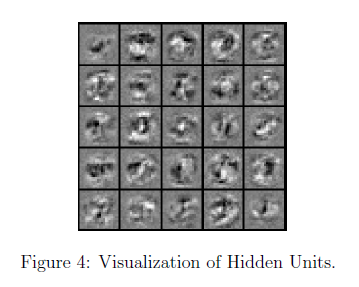

The code below does this by using the `displayData` function and it will show you an image (similar to Figure 4) with 25 units, each corresponding to one hidden unit in the network. In your trained network, you should find that the hidden units corresponds roughly to detectors that look for strokes and other patterns in the input.

% Visualize Weights 
displayData(Theta1(:, 2:end));

**It turns out that this is equivalent to finding the input that gives the highest activation for the hidden unit, given a 'norm' constraint on the input (i.e., *${\left\|x\right\|}_2 \le \;1$*).*

### 3.1 Optional (ungraded) exercise

In this part of the exercise, you will get to try out different learning settings for the neural network to see how the performance of the neural network varies with the regularization parameter and number of training steps (the `MaxIter` option when using `fmincg`). Neural networks are very powerful models that can form highly complex decision boundaries. Without regularization, it is possible for a neural network to 'overfit' a training set so that it obtains close to 100% accuracy on the training set but does not do as well on new examples that it has not seen before. You can set the regularization $\lambda$ to a smaller value and the `MaxIter` parameter to a higher number of iterations to see this for youself. You will also be able to see for yourself the changes in the visualizations of the hidden units when you change the learning parameters $\lambda$ and `MaxIter`.

% Change lambda and MaxIter to see how it affects the result
lambda = 3;
MaxIter = 50;

options = optimset('MaxIter', MaxIter);

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p,input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

% Visualize Weights 
displayData(Theta1(:, 2:end));

*You do not need to submit any solutions for this optional (ungraded) exercise.*

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

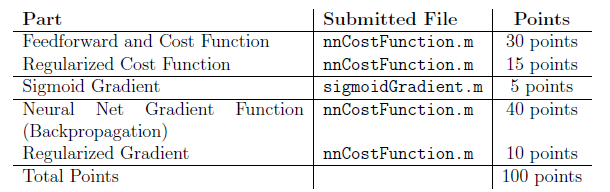

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.